# Investigate the spectral shape of vocalizations

Gathering spectral density function data of all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
QualityLog = fullfile(BaseDataDir, 'RecOnlyLogDeafSalQuality.txt');

% these are the list of files to analyse
if ~exist(QualityLog, 'file')
    error('Cannot find the list of file to anayse in: %s \n', QualityLog);
else
    FidQuality = fopen(QualityLog, 'r');
    Header = textscan(FidQuality,'%s\t%s\t%s\n',1);
    DoneListQuality = textscan(FidQuality,'%s\t%s\t%s');
    fclose(FidQuality);
end

% Find out the number of files to analyse
NToDo = length(DoneListQuality{1});
NF = nan(NToDo,1);
DataFiles = cell(1,NToDo);
for ff=1:NToDo
    % Get the BatID the Date and the time of the ff experiment 
    Date = DoneListQuality{2}{ff};
    ExpStartTime = DoneListQuality{3}{ff};
    Logger_dir = fullfile(BaseDataDir,['20' Date], 'audiologgers');
    DataFiles_local = dir(fullfile(Logger_dir, sprintf('%s_%s_VocExtractDat*_*.mat', Date, ExpStartTime)));
    NF(ff) = length(DataFiles_local);
    DataFiles{ff} = DataFiles_local';
end
DataFiles = [DataFiles{:}]';

Note the Auditory Loss function of bats:

load(fullfile(BaseDataDir, 'ABR_LossFunction.mat'), 'BatGain', 'FreqScale')
figure()
plot(FreqScale, BatGain, 'k-', 'LineWidth',2)
ylabel('Auditory Loss in dB')
xlabel('Frequency Hz')

 The auditory range span 3-60kHz with a particular sensitivity between 5-25kHz ( this has been reported elsewhere with sometimes a range that goes up to 50kHz with a reduce sensitivity at 32kHz. For the purpose of this study we want to restrict the spectral analysis to the zone that the bat can hear = frequencies with an auditory Loss value below 50dB

MinFreq = round(min(FreqScale(BatGain<=50))/10^3)*10^3;
MaxFreq = round(max(FreqScale(BatGain<=50))/10^3)*10^3;
fprintf(1,'Auditory range considered: %d-%d kHz', MinFreq/10^3, MaxFreq/10^3)

Auditory range considered: 2-60 kHz

Gather data from all calls elmts

NF = length(DataFiles);
F_high = MaxFreq;
BatID = cell(NF*100,1);
CallType = cell(NF*100,1);
MicAudioGood = nan(NF*100,1);
Spect_psd = cell(NF*100,1);
Spect_psd_audio = cell(NF*100,1);
Spect_psdf = cell(NF*100,1);
SpectAudio_Q=nan(NF*100,3);
SpectAudio_Mean=nan(NF*100,1);
SpectAudio_Std = nan(NF*100,1);
SpectAudio_Kurt = nan(NF*100,1);
SpectAudio_Skew = nan(NF*100,1);
SpectAudio_Ent = nan(NF*100,1);

VocCount = nan(NF,1);
warning('off', 'MATLAB:Python:UnsupportedLoad')
BatAudioGain = 10.^(-BatGain./10);
BatAudioGain = BatAudioGain./sum(BatAudioGain);
for nf = 1:NF
    fprintf(1,'File %d/%d\n', nf, NF);
    DataFile = load(fullfile(DataFiles(nf).folder, DataFiles(nf).name));
    if isempty(DataFile.BioSoundCalls)
        fprintf(1,'No Data for this file %s\n', DataFiles(nf).name)
        continue
    end
    VVCount = 0;
    for vv=1:size(DataFile.BioSoundFilenames,1)
        if isempty(DataFile.BioSoundFilenames{vv,2}) % That was probably an noise that have not been kept
            continue
        end
        [~,Name,~] = fileparts(DataFile.BioSoundFilenames{vv,2});
        NC_local = sum(DataFile.ManualAnnotationOK{vv}==1);
        IndCall = find(DataFile.ManualAnnotationOK{vv}==1);
        if iscell(DataFile.ManualCallType{vv}) && sum(~cellfun('isempty',DataFile.ManualCallType{vv}))~= NC_local
            error('There is an issue with the identification of syllables')
        elseif ~iscell(DataFile.ManualCallType{vv}) && ~isempty(DataFile.ManualCallType{vv})~= NC_local
            error('There is an issue with the identification of syllables')
        end
        BatInd = strfind(Name,'Bat');
        for ee=1:NC_local
            cc = IndCall(ee);
            VVCount = VVCount +1;
            BatID{VVCount+sum(VocCount, 'omitnan')} = Name(BatInd+(3:7));
            CallType{VVCount+sum(VocCount, 'omitnan')} = DataFile.ManualCallType{vv}{cc};
            if ~isempty(DataFile.AudioGood{vv}) % Issue here! AudioGood was not saved for part of the data!
                MicAudioGood(VVCount+sum(VocCount, 'omitnan')) = DataFile.AudioGood{vv}(cc);
            else
                warning('Looks like AudioGood was not saved for %s vv=%d', DataFiles(nf).name, vv)
                MicAudioGood(VVCount+sum(VocCount, 'omitnan')) = 0;
            end
%             if cc<=length(DataFile.BioSoundCalls{vv,1}.meanspect) % for some reason sometimes the last call is not prperly anayzed for microphone data under What_calls  -> Need to fix that at some point!!
            if length(DataFile.ManualAnnotationOK{vv})==1 || length(DataFile.BioSoundCalls{vv,1}.meanspect)==1
                [Pxx,F] = pwelch(DataFile.BioSoundCalls{vv,1}.sound,[],512,1024,DataFile.BioSoundCalls{vv,1}.samprate);
                GoodF = logical((F>=MinFreq).*(F<=MaxFreq));
                Spect_psd{VVCount+sum(VocCount, 'omitnan')} = Pxx(GoodF)./sum(Pxx(GoodF));
                % correct the spectrum with the auditory gain loss function
                PSD_audio = Spect_psd{VVCount+sum(VocCount, 'omitnan')}
                F = F(GoodF);
                for fo=1:length(F)
                    [~,IndF] = min(abs(F(fo)-FreqScale));
                    PSD_audio(fo) = PSD_audio(fo) .* BatAudioGain(IndF); % Pxx_audio(fo) = 10.*log10(Pxx(fo)) - BatGain(IndF); 
                end
                Spect_psd_audio{VVCount+sum(VocCount, 'omitnan')} = PSD_audio./sum(PSD_audio);
                Spect_psdf{VVCount+sum(VocCount, 'omitnan')} = F;
            elseif cc<= length(DataFile.BioSoundCalls{vv,1}.meanspect)
                IndOnOff = DataFile.BioSoundCalls{vv,1}.OnOffSets_elmts(cc,:);
                IndOnOff(2) = min(length(DataFile.BioSoundCalls{vv,1}.sound), IndOnOff(2));
                [Pxx,F] = pwelch(DataFile.BioSoundCalls{vv,1}.sound(IndOnOff(1):IndOnOff(2)),[],512,1024,DataFile.BioSoundCalls{vv,1}.samprate);
                GoodF = logical((F>=MinFreq).*(F<=MaxFreq));
                Spect_psd{VVCount+sum(VocCount, 'omitnan')} = Pxx(GoodF)./sum(Pxx(GoodF));
                % correct the spectrum with the auditory gain loss function
                PSD_audio = Spect_psd{VVCount+sum(VocCount, 'omitnan')};
                F = F(GoodF);
                for fo=1:length(F)
                    [~,IndF] = min(abs(F(fo)-FreqScale));
                    PSD_audio(fo) = PSD_audio(fo) .* BatAudioGain(IndF); % Pxx_audio(fo) = 10.*log10(Pxx(fo)) - BatGain(IndF); 
                end
                Spect_psd_audio{VVCount+sum(VocCount, 'omitnan')} = PSD_audio./sum(PSD_audio);
                Spect_psdf{VVCount+sum(VocCount, 'omitnan')} = F;
            elseif length(DataFile.ManualAnnotationOK{vv})>length(DataFile.BioSoundCalls{vv,1}.meanspect)
                warning('Looks like the last element was not analysed on the microphone for %s vv=%d', DataFiles(nf).name, vv)
                Spect_psd{VVCount+sum(VocCount, 'omitnan')} = NaN;
                Spect_psdf{VVCount+sum(VocCount, 'omitnan')} = NaN;
                Spect_psd_audio{VVCount+sum(VocCount, 'omitnan')} = NaN;
            else
                keyboard
            end
            if ~isnan(Spect_psdf{VVCount+sum(VocCount, 'omitnan')})
                [SpectAudio_Q(VVCount+sum(VocCount, 'omitnan'),:), SpectAudio_Mean(VVCount+sum(VocCount, 'omitnan')), SpectAudio_Std(VVCount+sum(VocCount, 'omitnan')), SpectAudio_Kurt(VVCount+sum(VocCount, 'omitnan')), SpectAudio_Skew(VVCount+sum(VocCount, 'omitnan')), SpectAudio_Ent(VVCount+sum(VocCount, 'omitnan'))] = spec_env_paramEstimate(Spect_psd_audio{VVCount+sum(VocCount, 'omitnan')},Spect_psdf{VVCount+sum(VocCount, 'omitnan')}, F_high);
            end
            % Figure
%              figure(); plot(F,Pxx./sum(Pxx), 'LineWidth',2); hold on; plot(F,Pxx_audio./sum(Pxx_audio), 'LineWidth',2); hold on;yyaxis right; hold on; plot(FreqScale, BatAudioGain, '--', 'LineWidth',2); hold off
%              legend('Original spectrum', 'Filtered Spectrum', 'Auditory Gain function')
%              xlabel('Frequency (Hz)')
%              ylabel('Power')
%             end
            
        end

    end
    VocCount(nf) = VVCount;
    fprintf(1, 'NCalls = %d\n', VVCount)
end

File 1/237


NCalls = 15


File 2/237


NCalls = 0


File 3/237


NCalls = 0


File 4/237


NCalls = 12


File 5/237


NCalls = 39


File 6/237


NCalls = 13


File 7/237


NCalls = 6


File 8/237


No Data for this file 200123_0958_VocExtractData8_200.mat


File 9/237


NCalls = 60


File 10/237


NCalls = 7


File 11/237


NCalls = 54


File 12/237


NCalls = 55


File 13/237


NCalls = 18


File 14/237


NCalls = 36


File 15/237


NCalls = 34


File 16/237


NCalls = 10


File 17/237


NCalls = 15


File 18/237


NCalls = 10


File 19/237


NCalls = 14


File 20/237


NCalls = 1


File 21/237


NCalls = 6


File 22/237


NCalls = 0


File 23/237


NCalls = 0


File 24/237


NCalls = 4


File 25/237


NCalls = 38


File 26/237


NCalls = 38


File 27/237


NCalls = 64


File 28/237


NCalls = 126


File 29/237


NCalls = 49


File 30/237


NCalls = 37


File 31/237


NCalls = 22


File 32/237


NCalls = 15


File 33/237


NCalls = 84


File 34/237


NCalls = 4


File 35/237


NCalls = 4


File 36/237


NCalls = 8


File 37/237


NCalls = 30


File 38/237


NCalls = 53


File 39/237


NCalls = 21


File 40/237


NCalls = 6


File 41/237


NCalls = 1


File 42/237


NCalls = 51


File 43/237


NCalls = 6


File 44/237


No Data for this file 200124_1013_VocExtractData21_200.mat


File 45/237


NCalls = 0


File 46/237


NCalls = 5


File 47/237


NCalls = 4


File 48/237


NCalls = 12


File 49/237


NCalls = 0


File 50/237


NCalls = 6


File 51/237


NCalls = 0


File 52/237


NCalls = 14


File 53/237


NCalls = 119


File 54/237


NCalls = 0


File 55/237


NCalls = 8


File 56/237


NCalls = 2


File 57/237


NCalls = 8


File 58/237


NCalls = 9


File 59/237


NCalls = 8


File 60/237


NCalls = 14


File 61/237


NCalls = 64


File 62/237


NCalls = 73


File 63/237


NCalls = 16


File 64/237


NCalls = 193


File 65/237


NCalls = 4


File 66/237


NCalls = 3


File 67/237


NCalls = 14


File 68/237


NCalls = 23


File 69/237


NCalls = 6


File 70/237


NCalls = 8


File 71/237


NCalls = 71


File 72/237


NCalls = 10


File 73/237


NCalls = 14


File 74/237


NCalls = 39


File 75/237


NCalls = 141


File 76/237


NCalls = 16


File 77/237


NCalls = 29


File 78/237


NCalls = 26


File 79/237


NCalls = 92


File 80/237


NCalls = 38


File 81/237


NCalls = 4


File 82/237


NCalls = 59


File 83/237


NCalls = 13


File 84/237


NCalls = 2


File 85/237


NCalls = 10


File 86/237


NCalls = 39


File 87/237


NCalls = 11


File 88/237


NCalls = 72


File 89/237


NCalls = 17


File 90/237


NCalls = 34


File 91/237


NCalls = 83


File 92/237


NCalls = 63


File 93/237


NCalls = 26


File 94/237


NCalls = 37


File 95/237


NCalls = 12


File 96/237


NCalls = 1


File 97/237


NCalls = 18


File 98/237


NCalls = 0


File 99/237


NCalls = 9


File 100/237


NCalls = 100


File 101/237


NCalls = 100


File 102/237


NCalls = 35


File 103/237


NCalls = 3


File 104/237


NCalls = 23


File 105/237


NCalls = 23


File 106/237


NCalls = 33


File 107/237


NCalls = 1


File 108/237


No Data for this file 200127_0959_VocExtractData27_200.mat


File 109/237


NCalls = 6


File 110/237


NCalls = 16


File 111/237


NCalls = 19


File 112/237


NCalls = 160


File 113/237


NCalls = 8


File 114/237


NCalls = 11


File 115/237


NCalls = 6


File 116/237


NCalls = 0


File 117/237


NCalls = 0


File 118/237


NCalls = 2


File 119/237


NCalls = 0


File 120/237


NCalls = 28


File 121/237


NCalls = 26


File 122/237


NCalls = 31


File 123/237


NCalls = 88


File 124/237


NCalls = 19


File 125/237


NCalls = 4


File 126/237


No Data for this file 200127_0959_VocExtractData43_200.mat


File 127/237


NCalls = 8


File 128/237


NCalls = 1


File 129/237


NCalls = 8


File 130/237


NCalls = 53


File 131/237


NCalls = 26


File 132/237


NCalls = 37


File 133/237


NCalls = 38


File 134/237


NCalls = 4


File 135/237


NCalls = 11


File 136/237


NCalls = 9


File 137/237


NCalls = 2


File 138/237


NCalls = 0


File 139/237


NCalls = 0


File 140/237


NCalls = 0


File 141/237


NCalls = 0


File 142/237


NCalls = 1


File 143/237


NCalls = 0


File 144/237


NCalls = 14


File 145/237


NCalls = 0


File 146/237


NCalls = 1


File 147/237


NCalls = 4


File 148/237


NCalls = 11


File 149/237


NCalls = 68


File 150/237


NCalls = 6


File 151/237


NCalls = 36


File 152/237


NCalls = 1


File 153/237


NCalls = 1


File 154/237


NCalls = 8


File 155/237


NCalls = 46


File 156/237


NCalls = 8


File 157/237


NCalls = 0


File 158/237


NCalls = 0


File 159/237


NCalls = 21


File 160/237


NCalls = 6


File 161/237


NCalls = 36


File 162/237


NCalls = 23


File 163/237


NCalls = 3


File 164/237


NCalls = 44


File 165/237


NCalls = 38


File 166/237


NCalls = 23


File 167/237


NCalls = 11


File 168/237


NCalls = 4


File 169/237


NCalls = 4


File 170/237


NCalls = 21


File 171/237


NCalls = 5


File 172/237


NCalls = 31


File 173/237


NCalls = 26


File 174/237


NCalls = 3


File 175/237


NCalls = 9


File 176/237


NCalls = 99


File 177/237


NCalls = 6


File 178/237


NCalls = 3


File 179/237


NCalls = 1


File 180/237


NCalls = 0


File 181/237


NCalls = 31


File 182/237


NCalls = 39


File 183/237


NCalls = 8


File 184/237


NCalls = 14


File 185/237


NCalls = 40


File 186/237


NCalls = 6


File 187/237


NCalls = 38


File 188/237


NCalls = 52


File 189/237


NCalls = 7


File 190/237


NCalls = 12


File 191/237


NCalls = 18


File 192/237


NCalls = 58


File 193/237


NCalls = 0


File 194/237


NCalls = 2


File 195/237


NCalls = 26


File 196/237


NCalls = 39


File 197/237


NCalls = 9


File 198/237


NCalls = 3


File 199/237


NCalls = 4


File 200/237


NCalls = 147


File 201/237


NCalls = 23


File 202/237


NCalls = 11


File 203/237


NCalls = 1


File 204/237


NCalls = 2


File 205/237


NCalls = 3


File 206/237


NCalls = 26


File 207/237


NCalls = 14


File 208/237


NCalls = 14


File 209/237


NCalls = 15


File 210/237


NCalls = 50


File 211/237


NCalls = 72


File 212/237


NCalls = 173


File 213/237


NCalls = 124


File 214/237


NCalls = 25


File 215/237


NCalls = 78


File 216/237


NCalls = 24


File 217/237


NCalls = 57


File 218/237


NCalls = 38


File 219/237


NCalls = 16


File 220/237


NCalls = 10


File 221/237


NCalls = 12


File 222/237


NCalls = 47


File 223/237


NCalls = 28


File 224/237


NCalls = 17


File 225/237


NCalls = 43


File 226/237


NCalls = 43


File 227/237


NCalls = 4


File 228/237


NCalls = 33


File 229/237


NCalls = 9


File 230/237


NCalls = 20


File 231/237


NCalls = 53


File 232/237


NCalls = 3


File 233/237


NCalls = 1


File 234/237


NCalls = 10


File 235/237


NCalls = 3


File 236/237


NCalls = 11


File 237/237


NCalls = 2


warning('on', 'MATLAB:Python:UnsupportedLoad')

NCalls = sum(VocCount, 'omitnan');
fprintf(1, 'Total number of detected and cut-out call elements: %d\n', NCalls)

Total number of detected and cut-out call elements: 5894


BatID = BatID(1:NCalls);
CallType = CallType(1:NCalls);
MicAudioGood = MicAudioGood(1:NCalls);
Spect_psdf = Spect_psdf(1:NCalls);
Spect_psd = Spect_psd(1:NCalls);
Spect_psd_audio = Spect_psd_audio(1:NCalls);
SpectAudio_Q = SpectAudio_Q(1:NCalls,:);
SpectAudio_Mean = SpectAudio_Mean(1:NCalls,:);
SpectAudio_Std = SpectAudio_Std(1:NCalls,:);
SpectAudio_Kurt = SpectAudio_Kurt(1:NCalls,:);
SpectAudio_Skew = SpectAudio_Skew(1:NCalls,:);
SpectAudio_Ent = SpectAudio_Ent(1:NCalls,:);
Old = load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'), 'BatID', 'CallType', 'MicAudioGood')

Old = struct with fields:
           BatID: {5894×1 cell}
        CallType: {5894×1 cell}
    MicAudioGood: [5894×1 double]


if prod(strcmp(BatID, Old.BatID)) && prod(strcmp(CallType, Old.CallType)) && prod(MicAudioGood==Old.MicAudioGood)
    save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'), 'Spect_psdf','Spect_psd','Spect_psd_audio','SpectAudio_Q', 'SpectAudio_Mean', 'SpectAudio_Std','SpectAudio_Kurt', 'SpectAudio_Skew','SpectAudio_Ent', '-append');
end
clear Old

## Get the average spectrum for each bat within each Acoustic cluster

load all data

load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'))

% Get the color vector ready for Batname
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 0 0 0];
UBat = unique(BatID);
CBat = nan(length(BatID),3);
for bat=1:length(UBat)
    CBat(contains(BatID,UBat(bat)),:) = repmat(ColorCode(bat,:),sum(contains(BatID,UBat(bat))),1);
end

% Get the color vector ready for Sex and Deafness
Path2RecordingTable = '/Volumes/GoogleDrive/My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx';
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(length(BatName),1);
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end

end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);

% AcousticClusters = nan(size(Deaf));
% AcousticClusters(strcmp(Deaf, 'D')) = TD;
% AcousticClusters(strcmp(Deaf, 'H')) = T;
AcousticClusters = TAll;

UCat = unique(AcousticClusters);


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


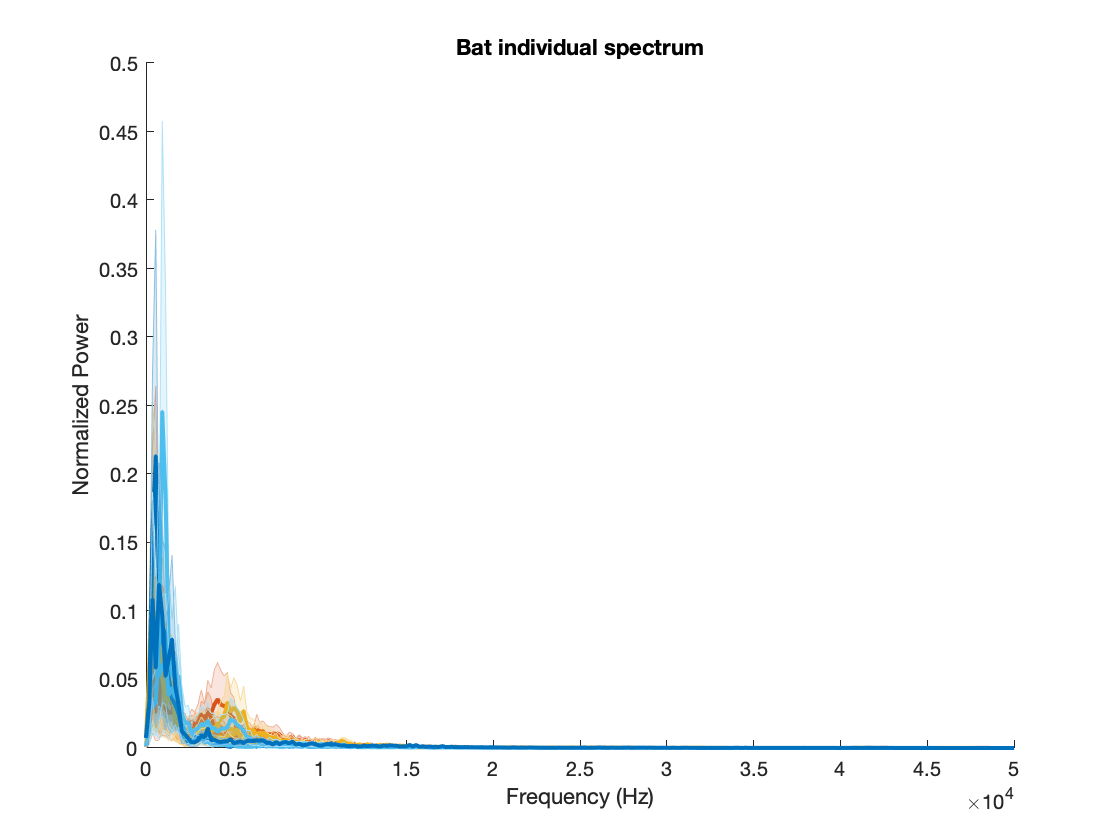

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


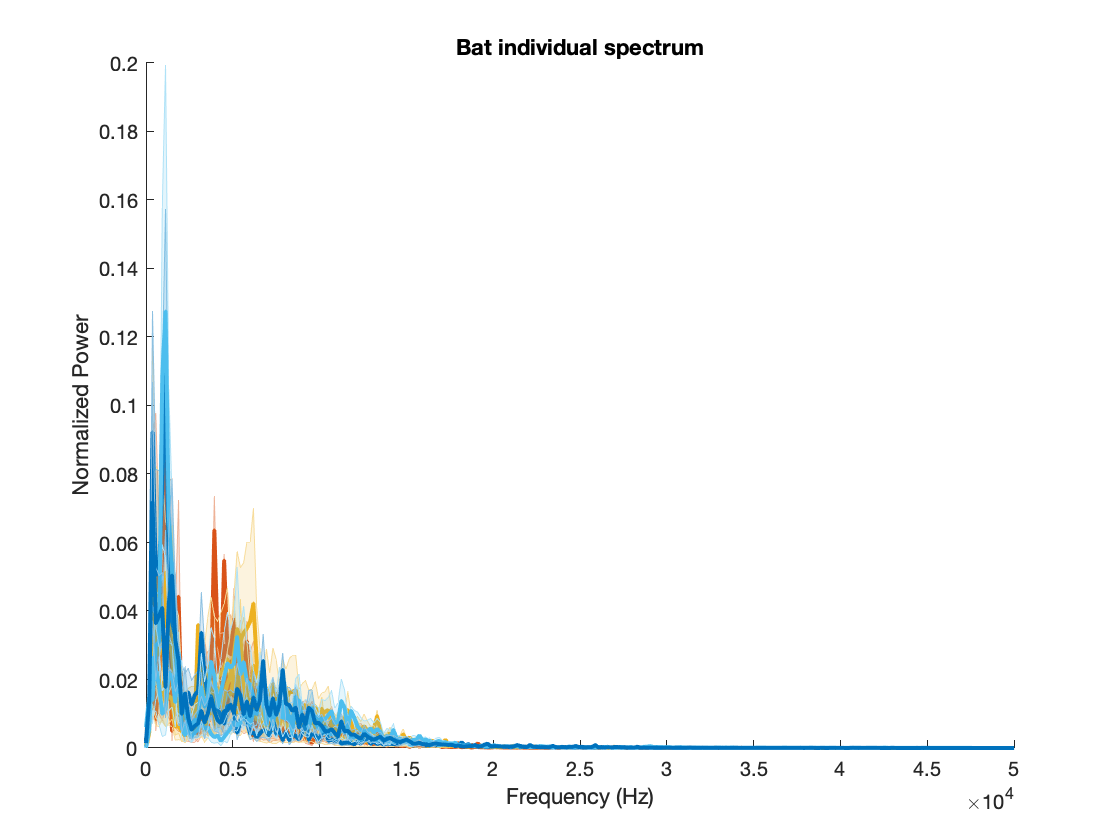

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


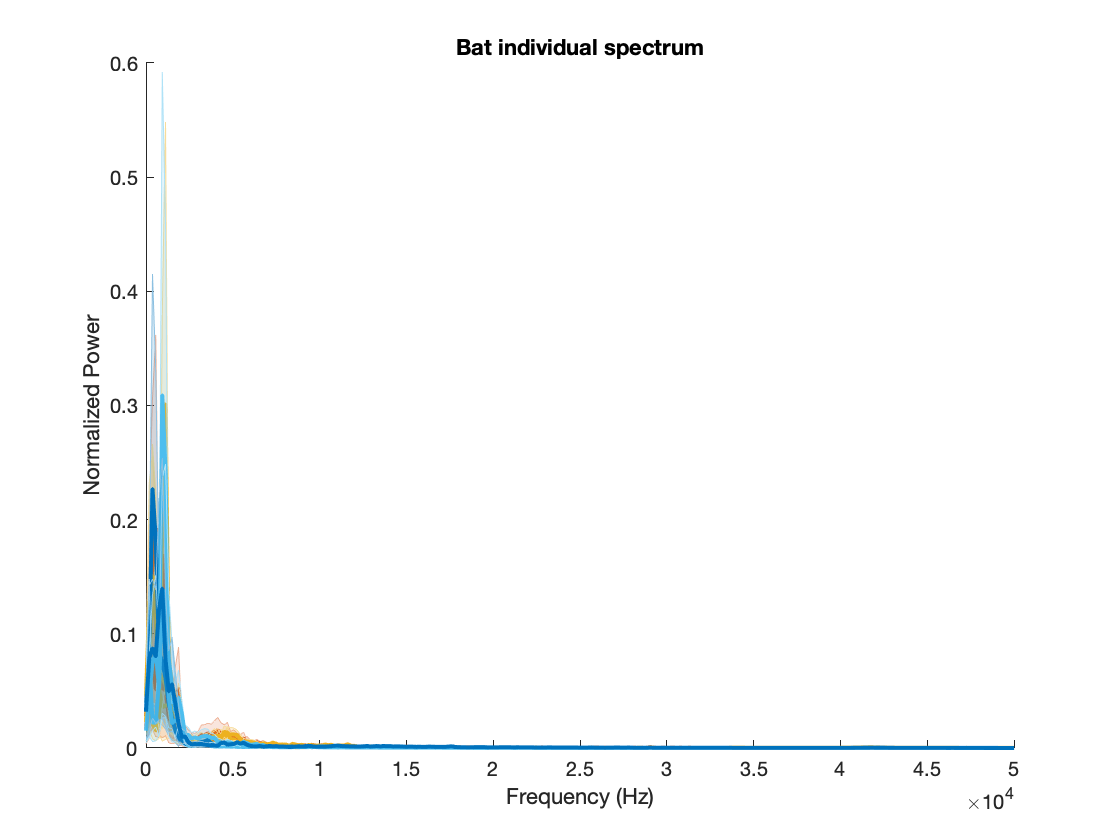

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


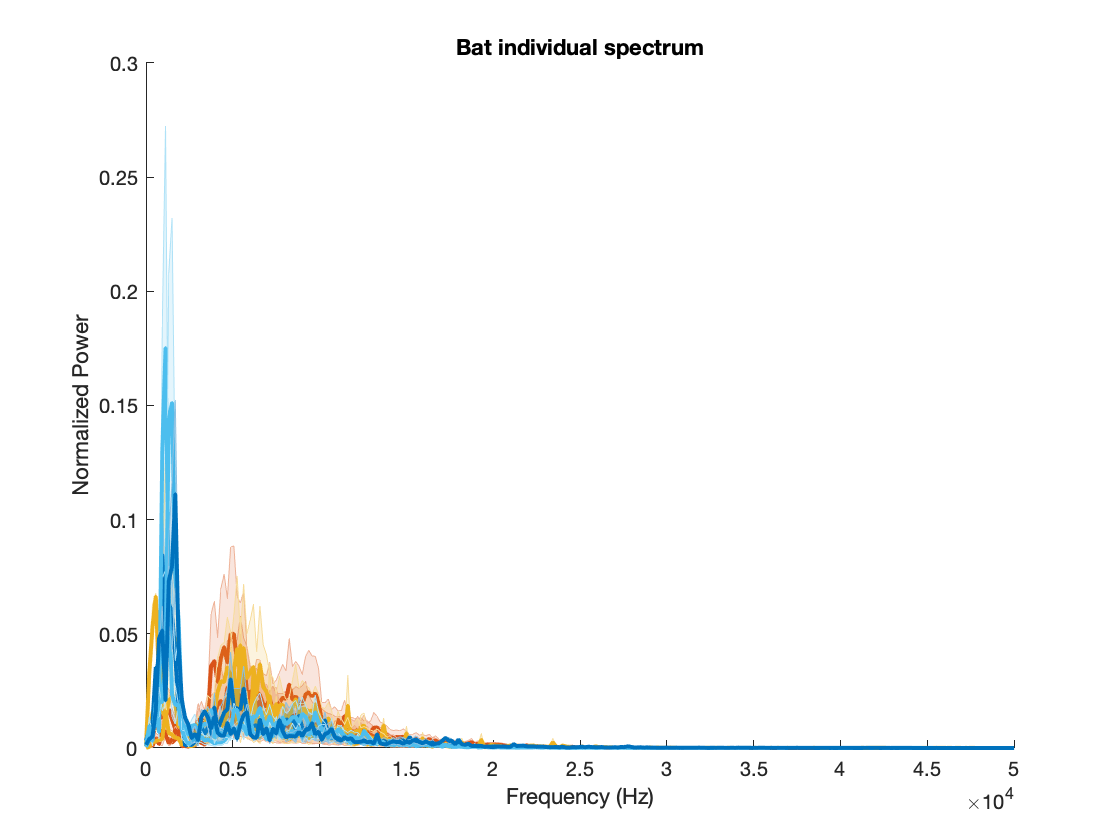

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


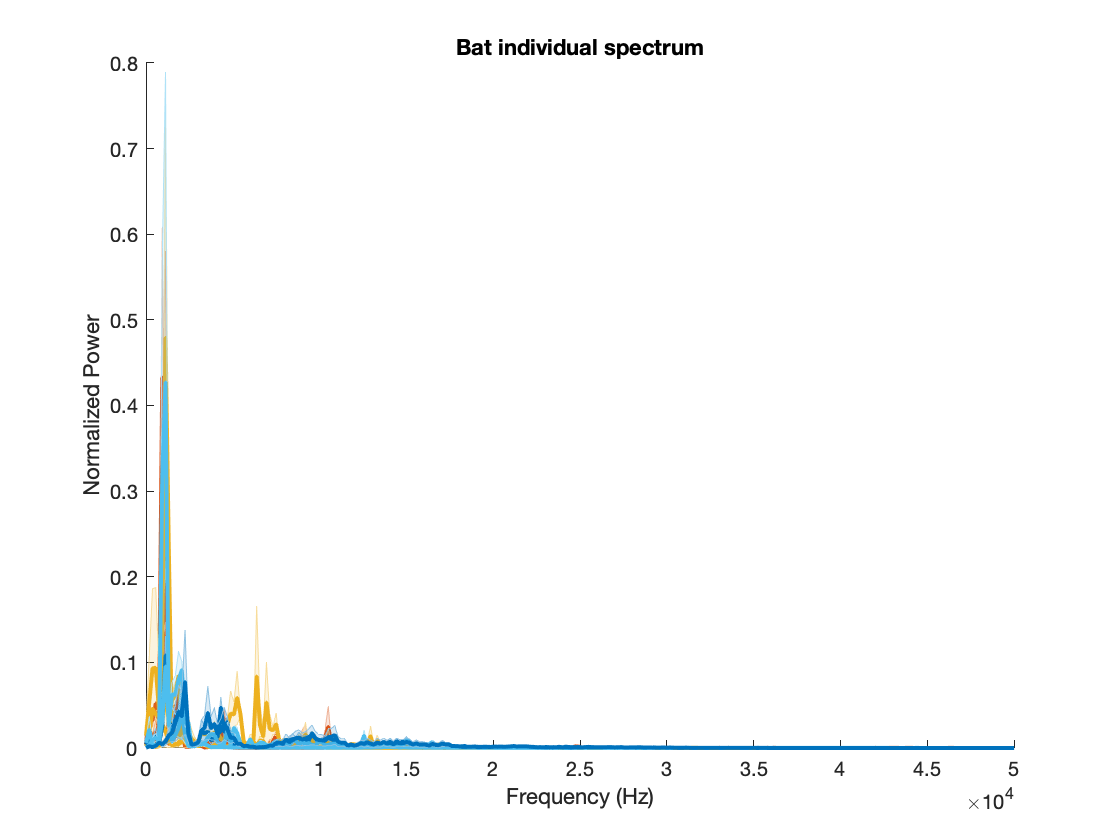

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


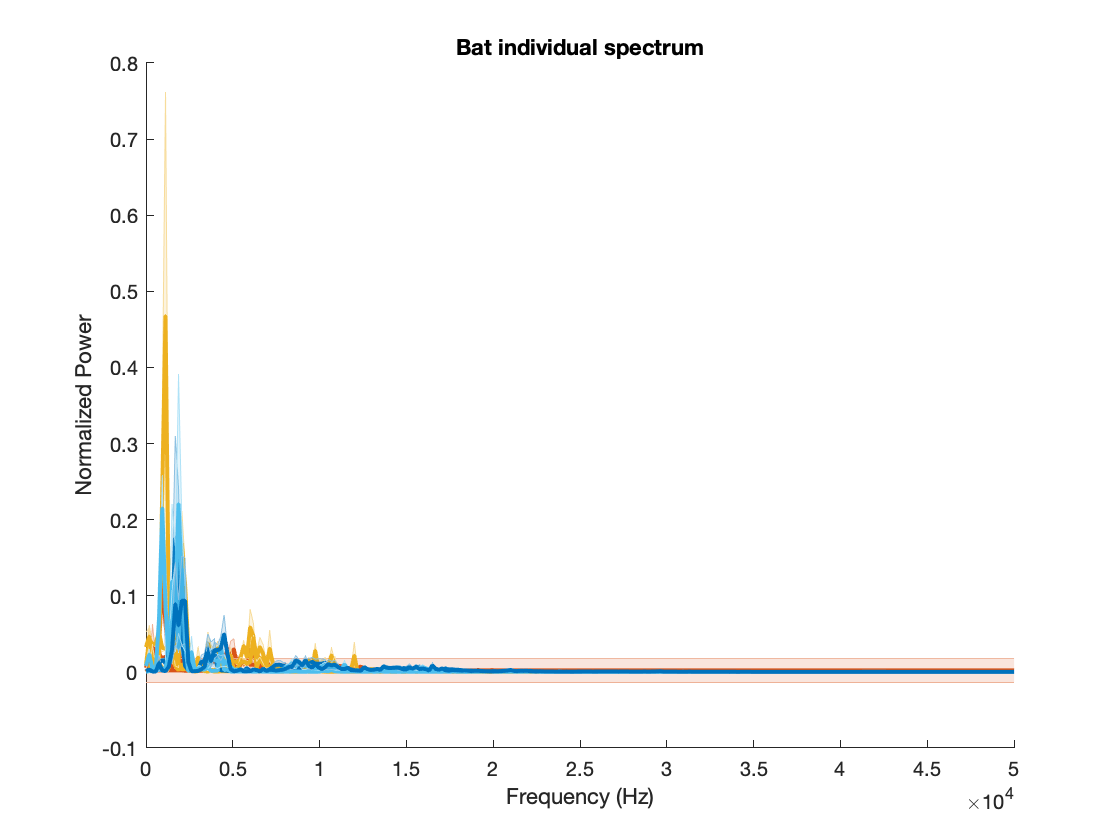

AcVar_mean_pBat = nan(length(BatName), length(Spect_psd{1}), length(UCat));
AcVar_se_pBat = AcVar_mean_pBat;
for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    
    Col_local = nan(length(BatName),3);
    figure()
    for bb=1:length(BatName)
        Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))) .* (cellfun(@length, Spect_psdf)~=1));
        AcVar_mean_pBat(bb,:,cc) = mean(cell2mat(Spect_psd(Ind)')', 'omitnan');
        AcVar_se_pBat(bb,:,cc) = std(cell2mat(Spect_psd(Ind)')', 'omitnan')./sum(Ind)^0.5;
        Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
        hold on
%         plot(Spect_psdf{find(Ind,1)},AcVar_mean_pBat(bb,:),'-', 'Color', [Col_local(bb,:) 0.7], 'LineWidth',2)
        shadedErrorBar(Spect_psdf{find(Ind,1)},AcVar_mean_pBat(bb,:,cc), [AcVar_mean_pBat(bb,:,cc)-2.*AcVar_se_pBat(bb,:,cc); AcVar_mean_pBat(bb,:,cc)-2.*AcVar_se_pBat(bb,:,cc)], {'-', 'Color', Col_local(bb,:), 'LineWidth',2},1)
    end
    hold off
    set(gca,'XLim', [0 50000])
%     set(gca, 'XScale','log')
    xlabel('Frequency (Hz)')
    ylabel('Normalized Power')
    title('Bat individual spectrum')
end

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


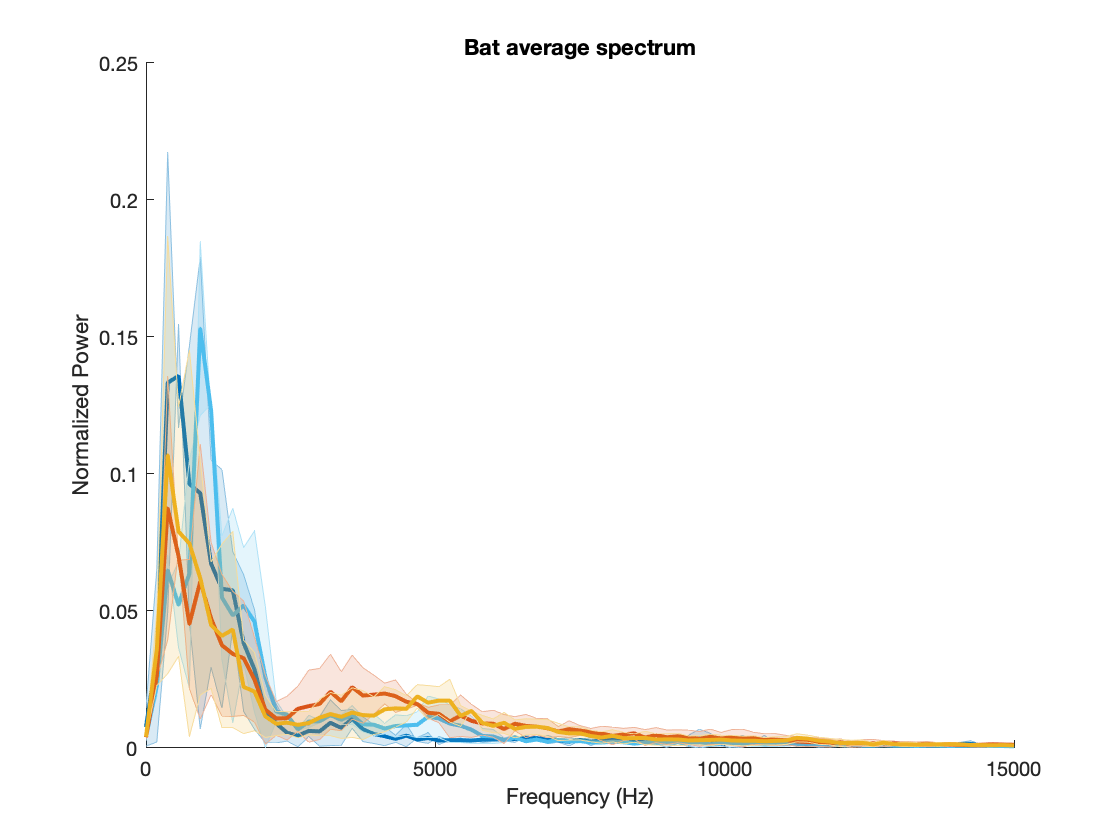

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


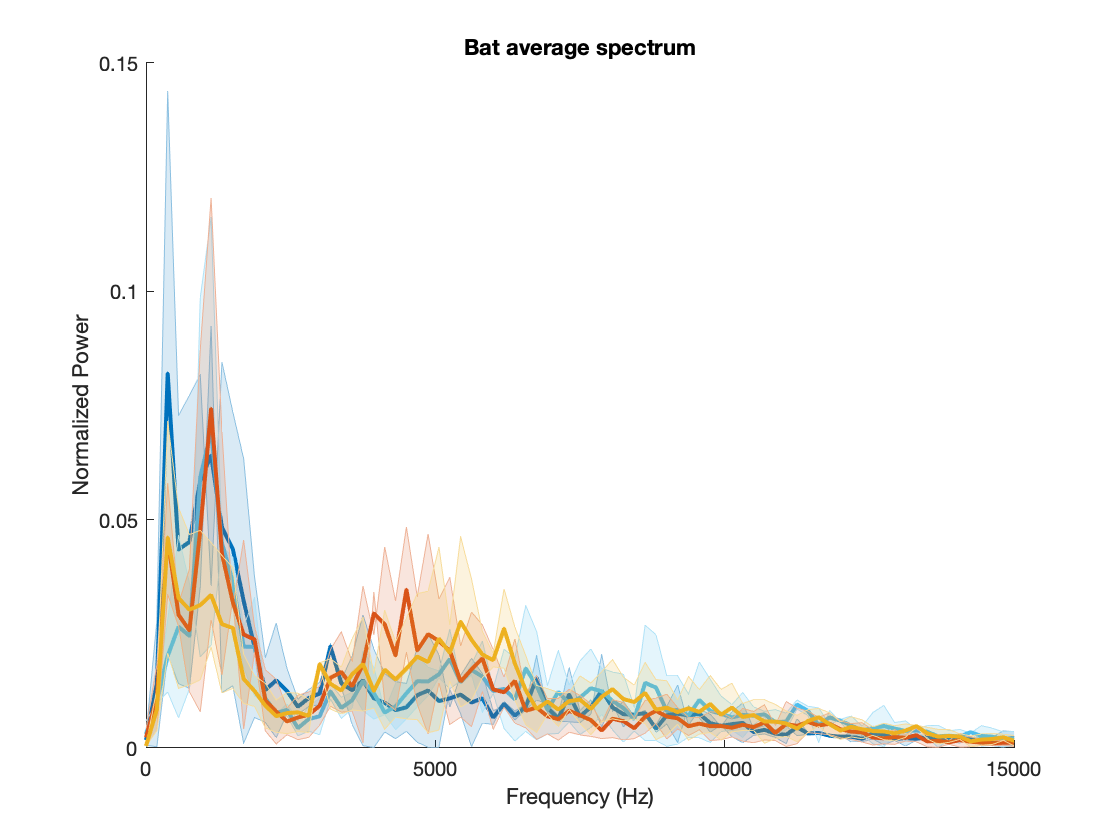

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


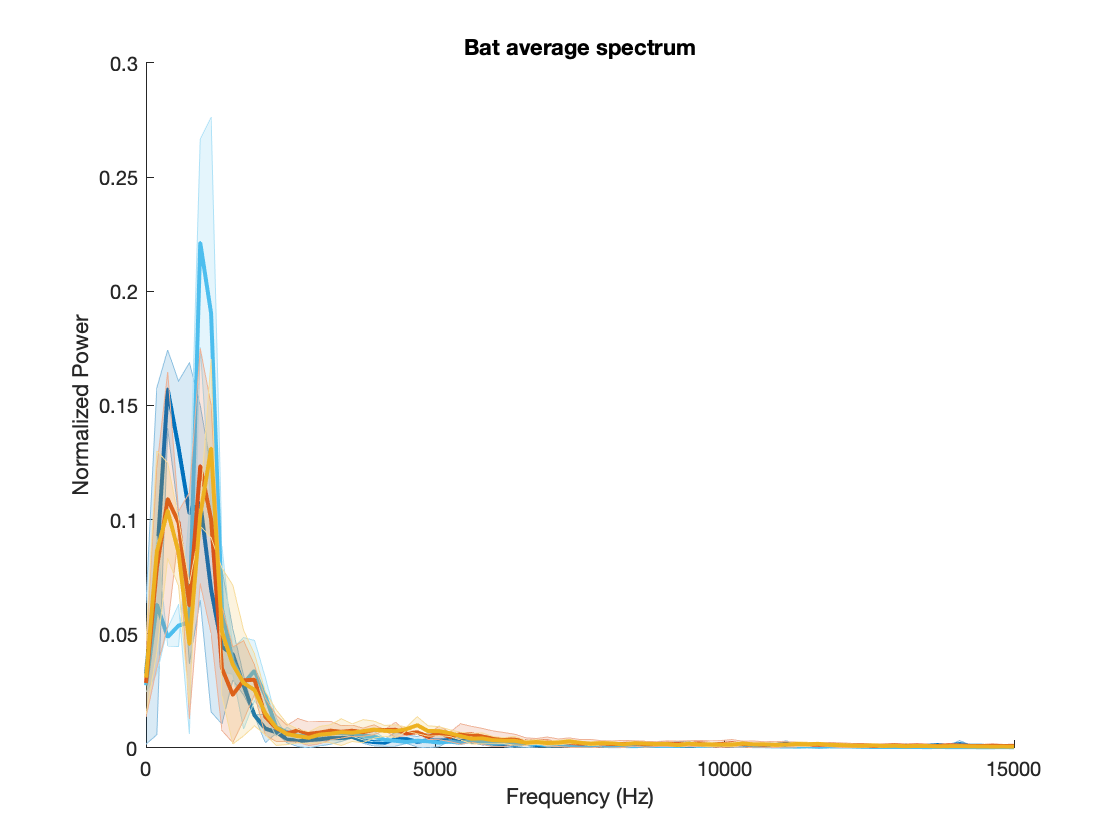

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


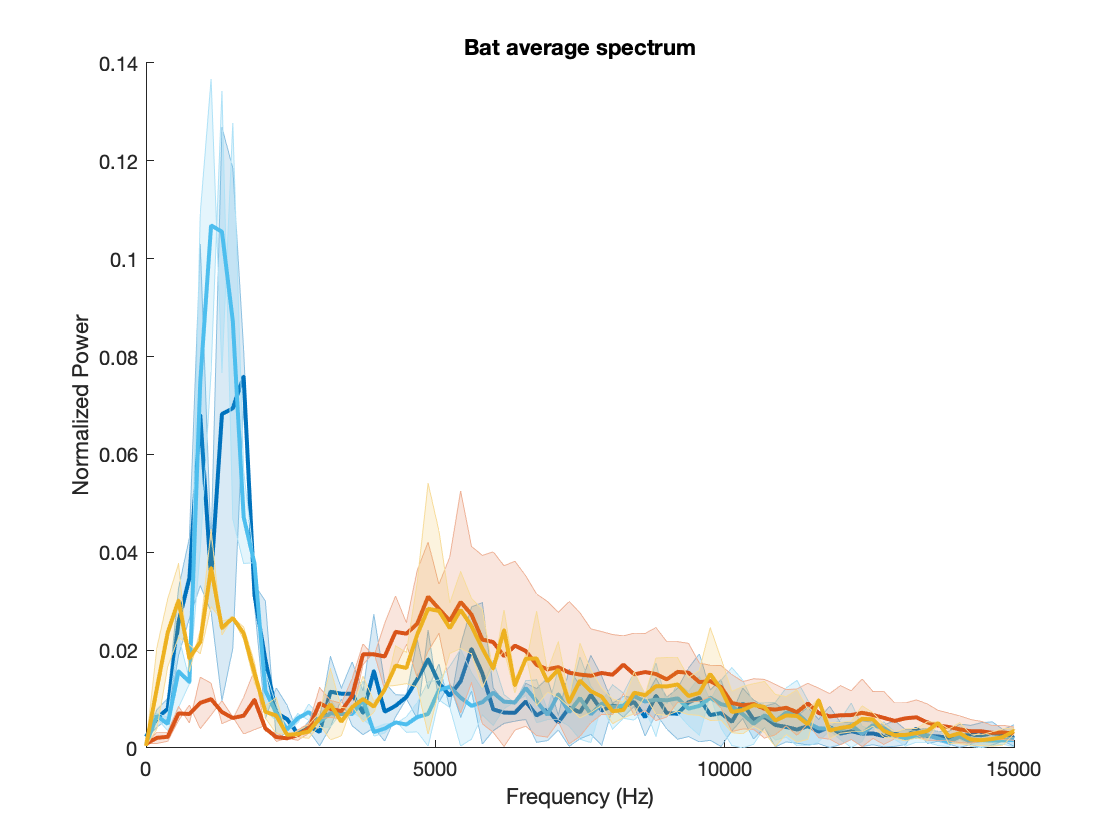

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


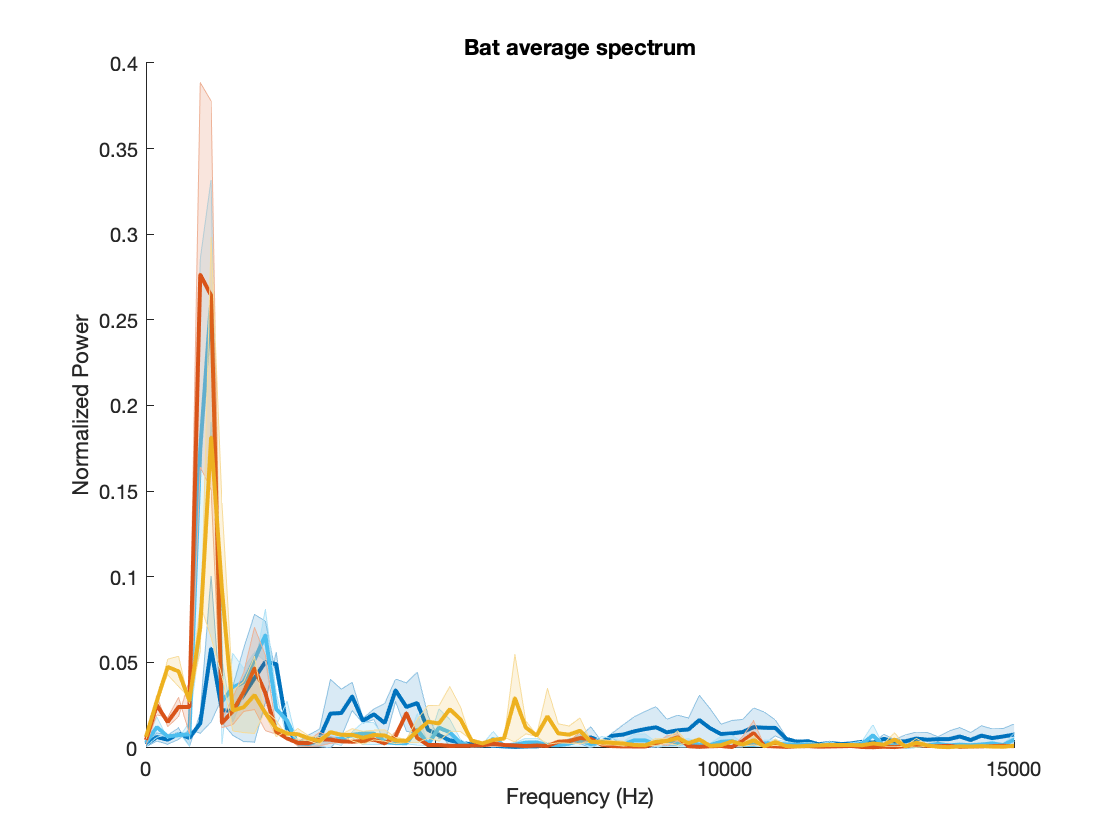

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


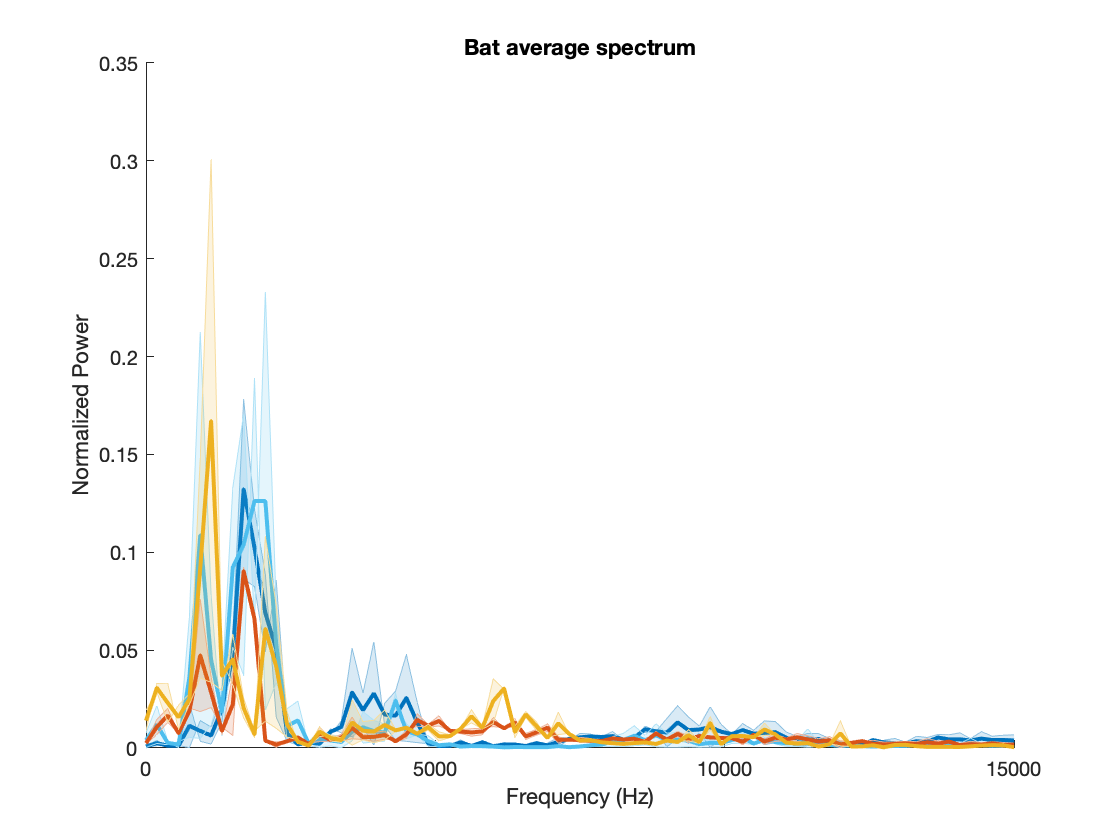

for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    figure()
    for bb=1:length(USexDeaf)
        Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))) .* (cellfun(@length, Spect_psdf)~=1));
        AcVar_mean_pSD = mean(AcVar_mean_pBat(contains(BatSexDeaf,USexDeaf{bb}),:, cc));
        AcVar_se_pSD = std(AcVar_mean_pBat(contains(BatSexDeaf,USexDeaf{bb}),:,cc))./sum(contains(BatSexDeaf,USexDeaf{bb}))^0.5;
        Col_local = UCSexDeaf(bb,:);
        hold on
%         plot(Spect_psdf{find(Ind,1)},AcVar_mean_pBat(bb,:),'-', 'Color', [Col_local(bb,:) 0.7], 'LineWidth',2)
        shadedErrorBar(Spect_psdf{find(Ind,1)},AcVar_mean_pSD, [AcVar_mean_pSD-2.*AcVar_se_pSD; AcVar_mean_pSD-2.*AcVar_se_pSD], {'-', 'Color', Col_local, 'LineWidth',2},1)
    end
    hold off
    set(gca,'XLim', [0 15000])
%     set(gca, 'XScale','log')
    xlabel('Frequency (Hz)')
    ylabel('Normalized Power')
    title('Bat average spectrum')
end

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


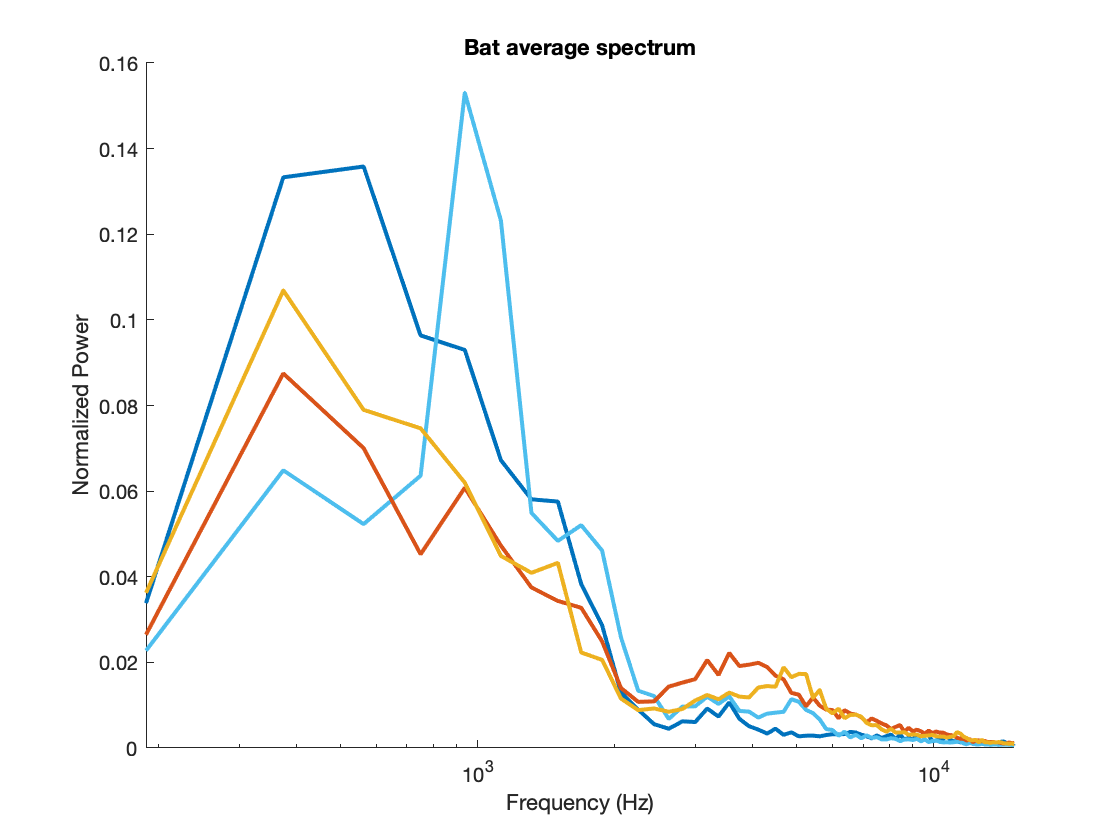

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


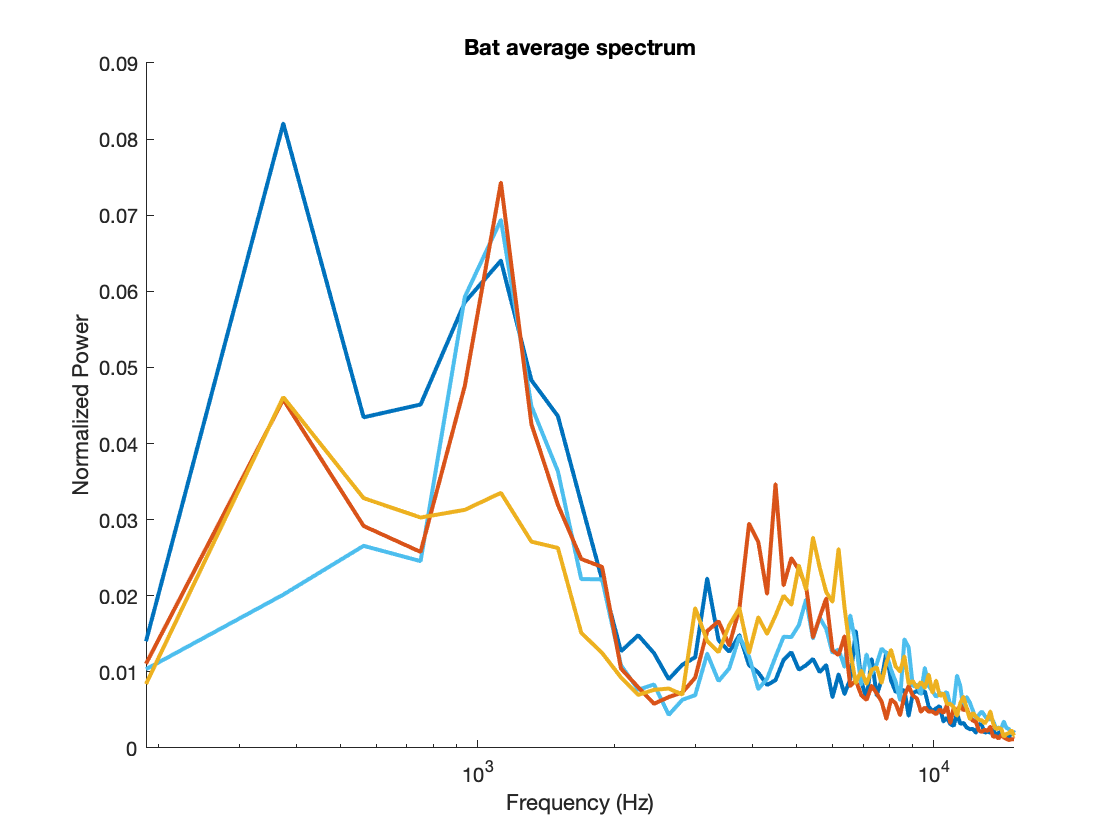

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


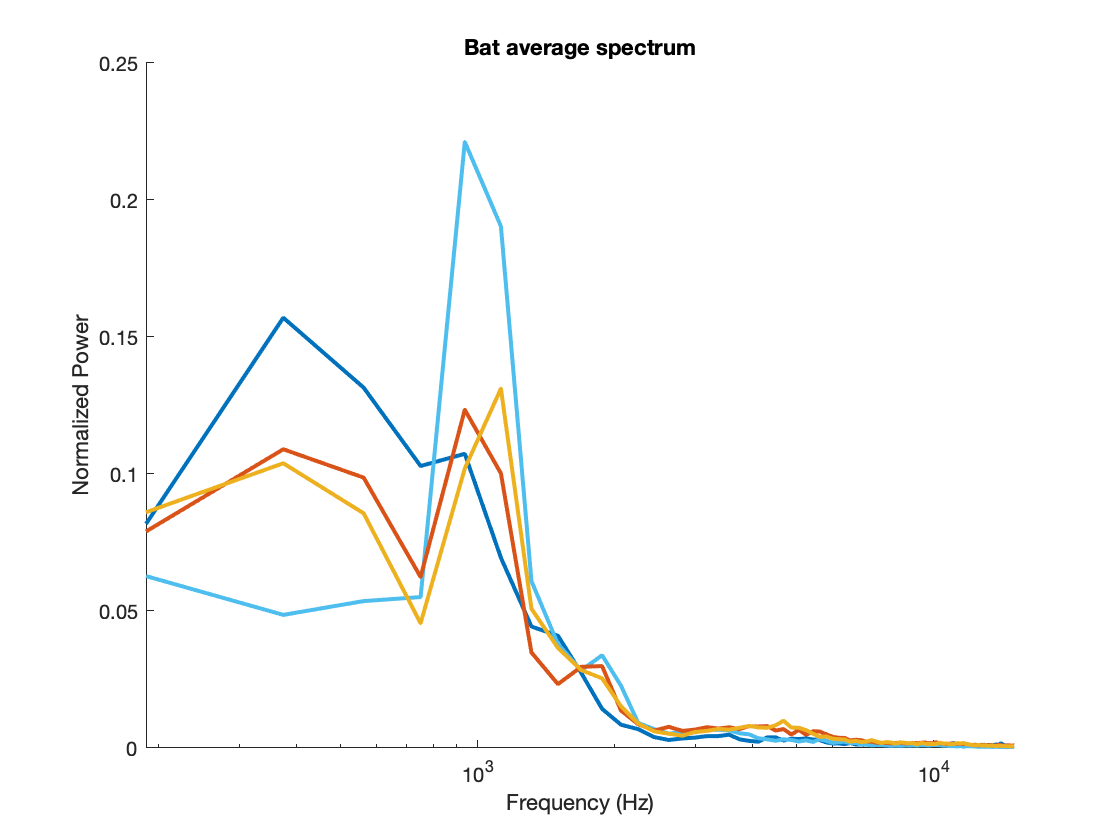

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


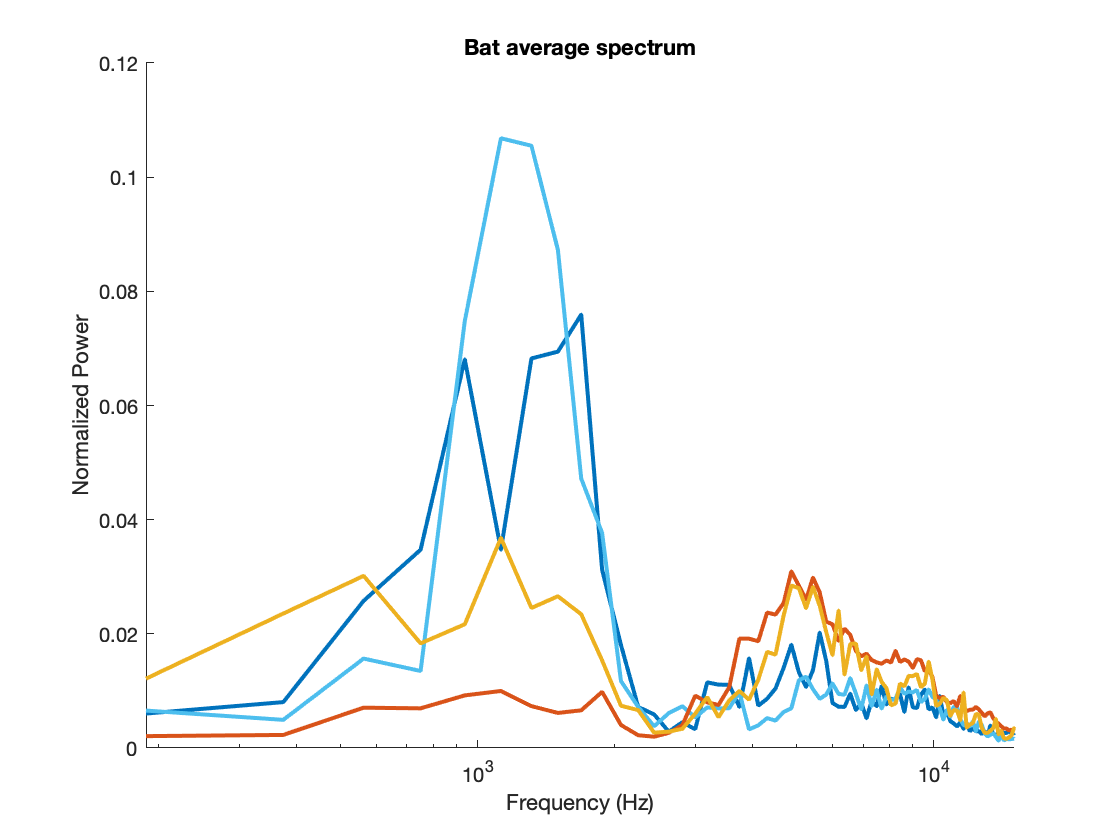

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


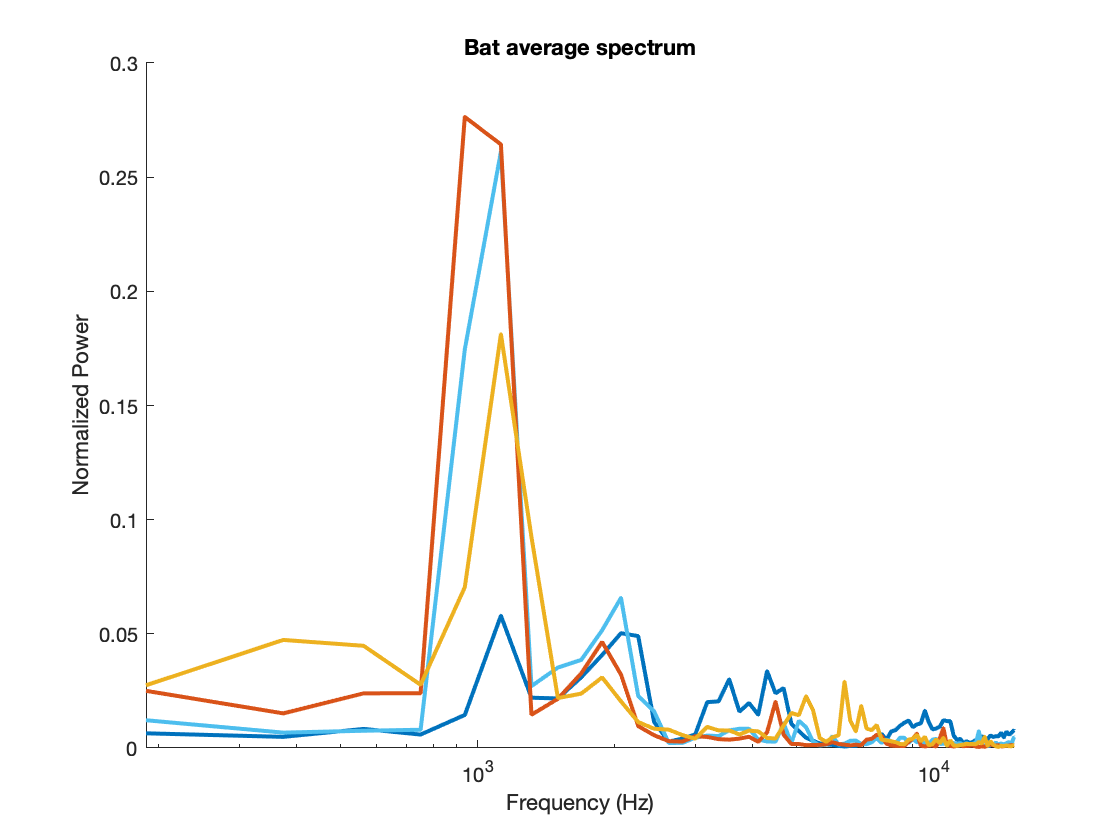

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


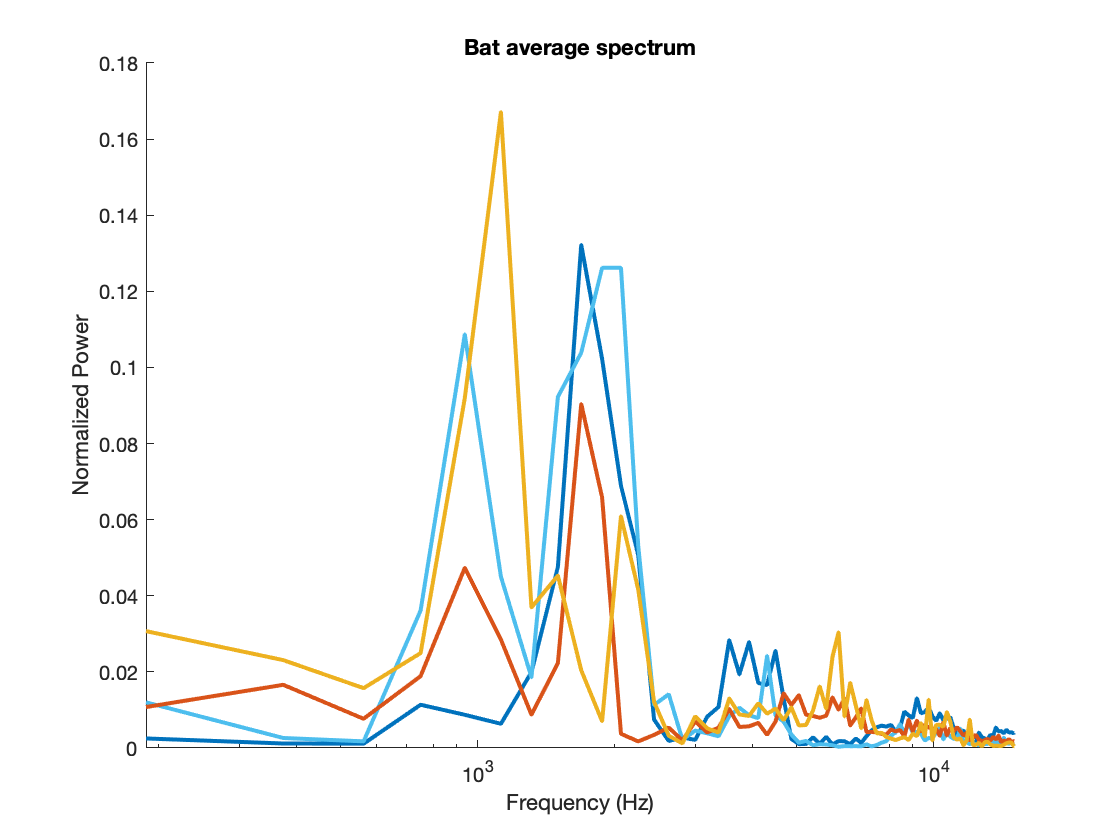

for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    figure()
    for bb=1:length(USexDeaf)
        Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))) .* (cellfun(@length, Spect_psdf)~=1));
        AcVar_mean_pSD = mean(AcVar_mean_pBat(contains(BatSexDeaf,USexDeaf{bb}),:, cc));
        AcVar_se_pSD = std(AcVar_mean_pBat(contains(BatSexDeaf,USexDeaf{bb}),:,cc))./sum(contains(BatSexDeaf,USexDeaf{bb}))^0.5;
        Col_local = UCSexDeaf(bb,:);
        hold on
        plot(Spect_psdf{find(Ind,1)},AcVar_mean_pSD, '-', 'Color', [Col_local 0.75], 'LineWidth',2)
    end
    hold off
    set(gca,'XLim', [0 15000])
    set(gca, 'XScale','log')
    xlabel('Frequency (Hz)')
    ylabel('Normalized Power')
    title('Bat average spectrum')
end

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


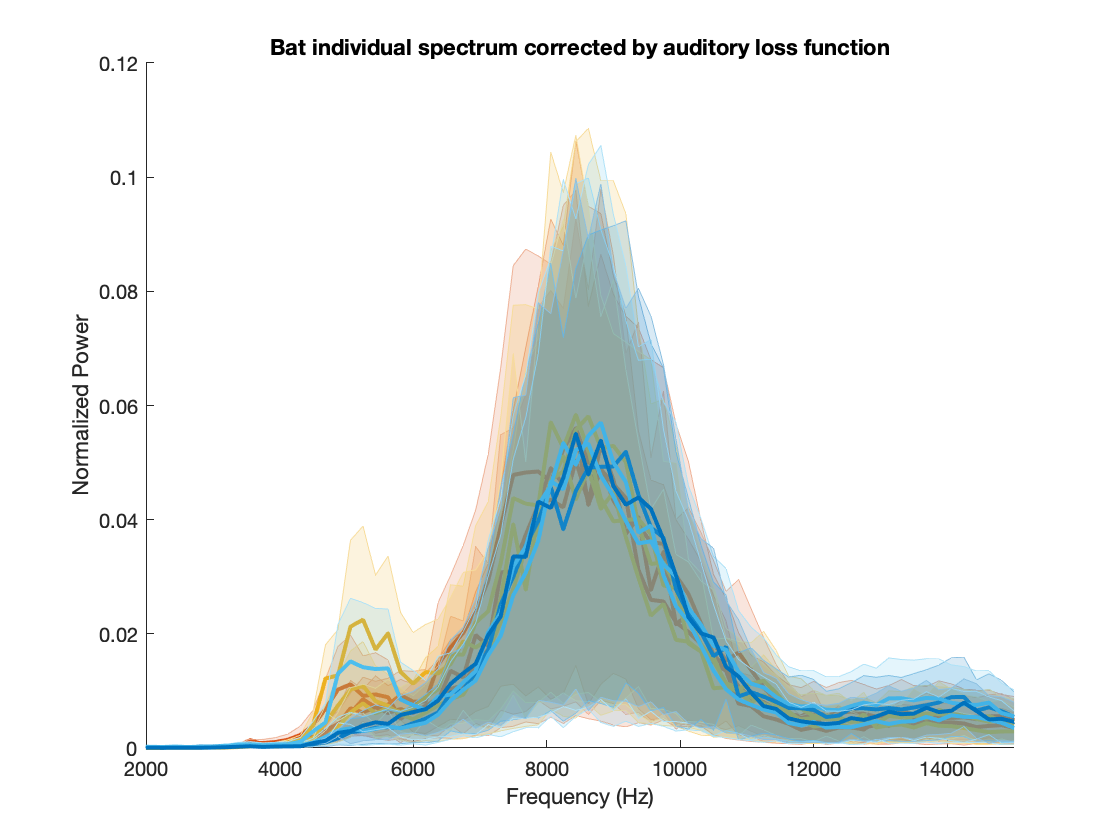

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


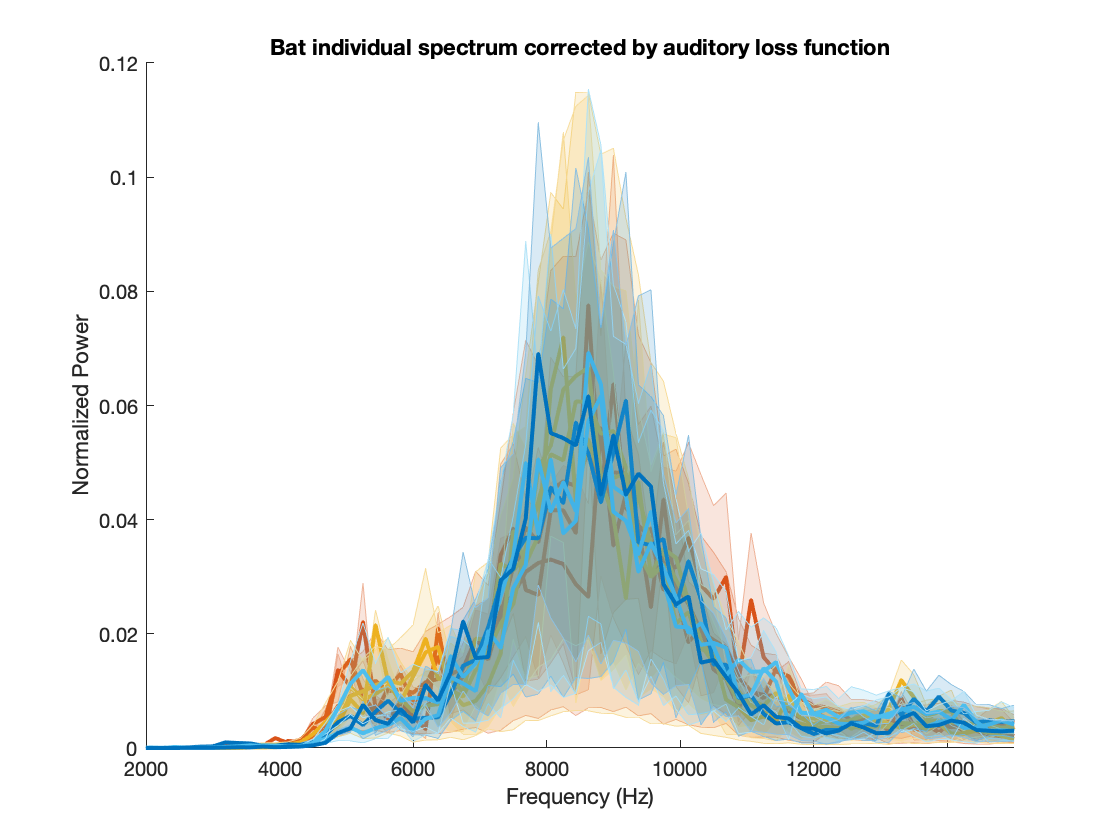

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


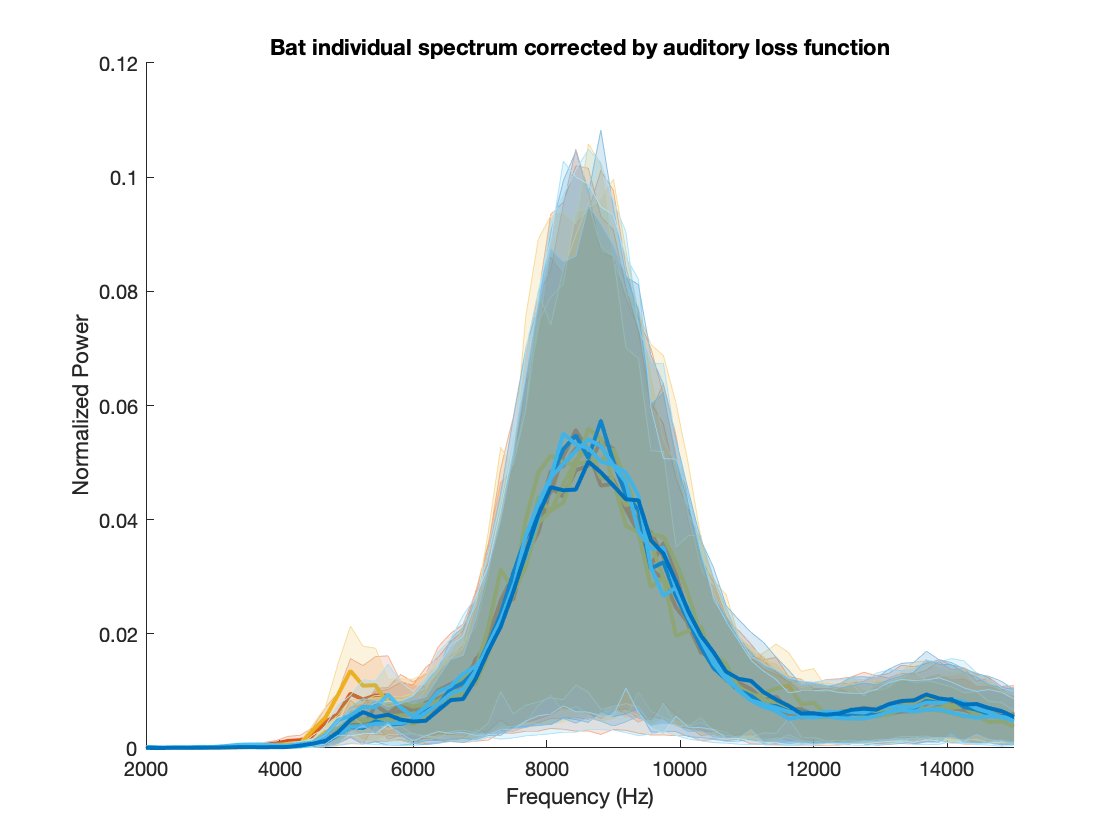

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


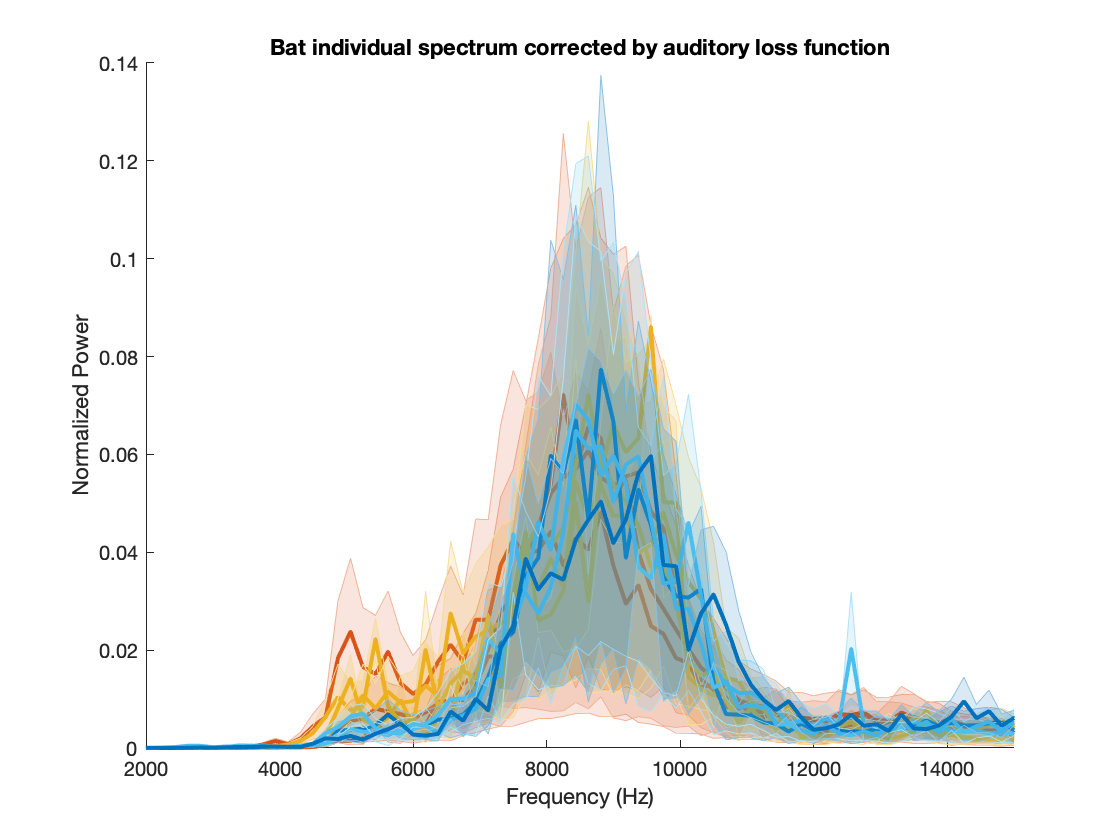

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


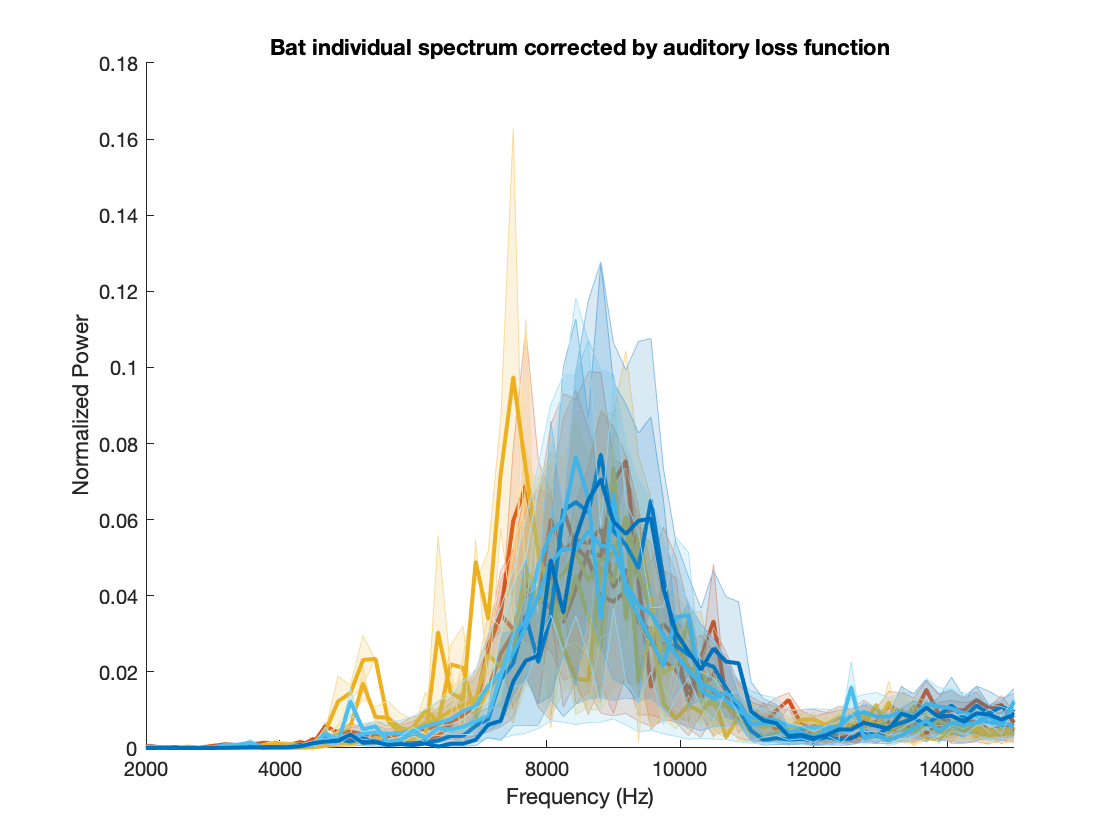

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


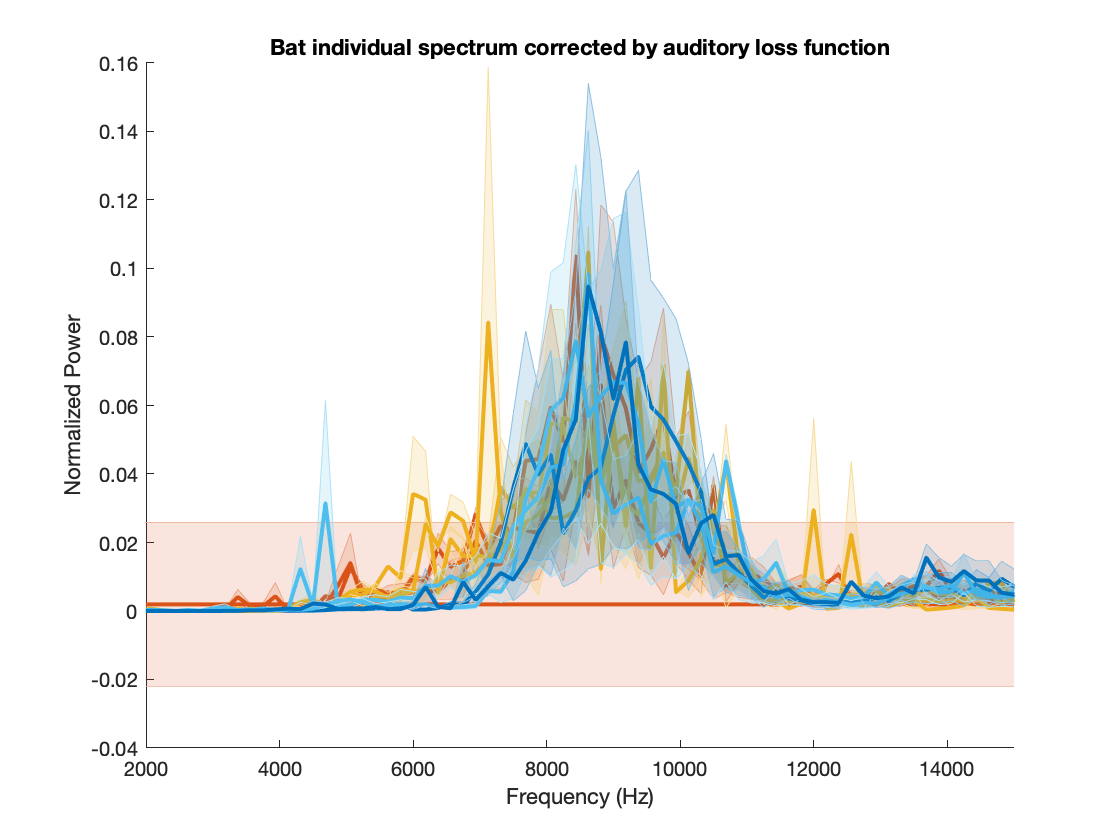

AcVar_mean_pBat = nan(length(BatName), length(Spect_psd_audio{1}), length(UCat));
AcVar_se_pBat = AcVar_mean_pBat;
for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    
    Col_local = nan(length(BatName),3);
    figure()
    for bb=1:length(BatName)
        Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))) .* (cellfun(@length, Spect_psdf)~=1));
        AcVar_mean_pBat(bb,:,cc) = mean(cell2mat(Spect_psd_audio(Ind)')', 'omitnan');
        AcVar_se_pBat(bb,:,cc) = std(cell2mat(Spect_psd_audio(Ind)')', 'omitnan')./sum(Ind)^0.5;
        Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
        hold on
%         plot(Spect_psdf{find(Ind,1)},AcVar_mean_pBat(bb,:),'-', 'Color', [Col_local(bb,:) 0.7], 'LineWidth',2)
        shadedErrorBar(Spect_psdf{find(Ind,1)},AcVar_mean_pBat(bb,:,cc), [AcVar_mean_pBat(bb,:,cc)-2.*AcVar_se_pBat(bb,:,cc); AcVar_mean_pBat(bb,:,cc)-2.*AcVar_se_pBat(bb,:,cc)], {'-', 'Color', Col_local(bb,:), 'LineWidth',2},1)
    end
    hold off
    set(gca,'XLim', [2000 15000])
%     set(gca, 'XScale','log')
    xlabel('Frequency (Hz)')
    ylabel('Normalized Power')
    title('Bat individual spectrum corrected by auditory loss function')
end

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


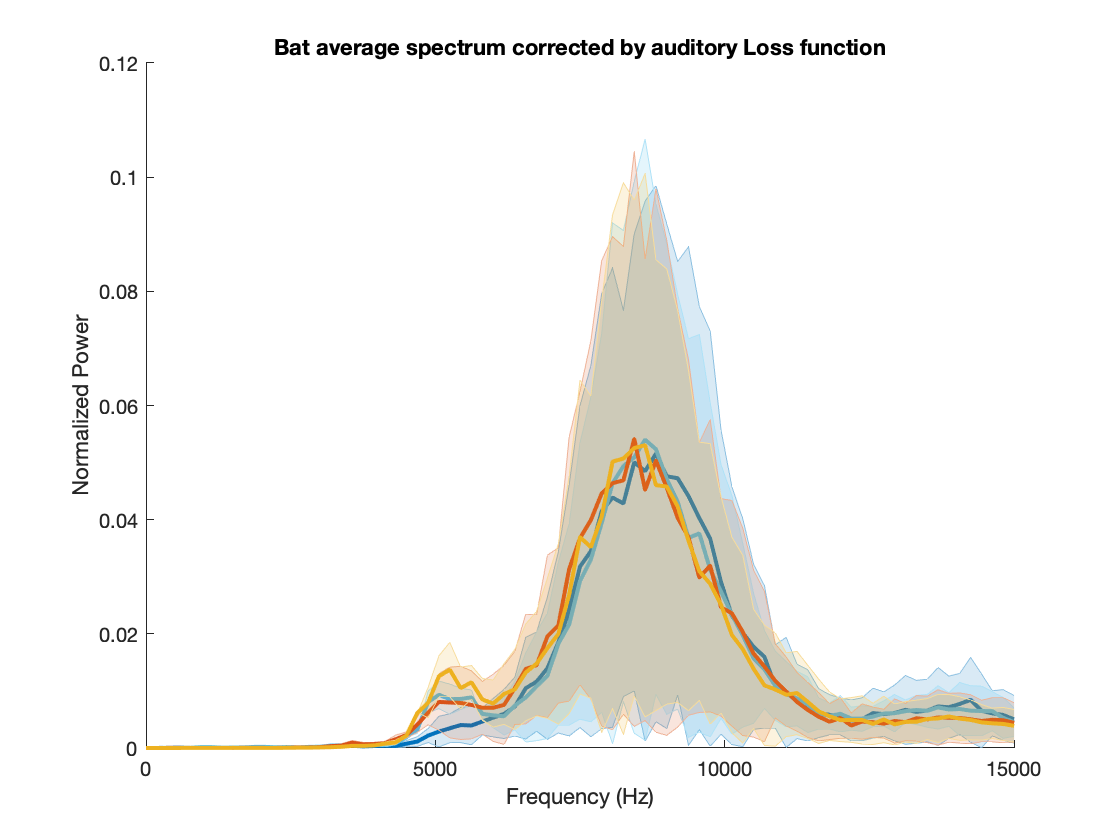

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    figure()
    for bb=1:length(USexDeaf)
        Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))) .* (cellfun(@length, Spect_psdf)~=1));
        AcVar_mean_pSD = mean(AcVar_mean_pBat(contains(BatSexDeaf,USexDeaf{bb}),:, cc));
        AcVar_se_pSD = std(AcVar_mean_pBat(contains(BatSexDeaf,USexDeaf{bb}),:,cc))./sum(contains(BatSexDeaf,USexDeaf{bb}))^0.5;
        Col_local = UCSexDeaf(bb,:);
        hold on
%         plot(Spect_psdf{find(Ind,1)},AcVar_mean_pBat(bb,:),'-', 'Color', [Col_local(bb,:) 0.7], 'LineWidth',2)
        shadedErrorBar(Spect_psdf{find(Ind,1)},AcVar_mean_pSD, [AcVar_mean_pSD-2.*AcVar_se_pSD; AcVar_mean_pSD-2.*AcVar_se_pSD], {'-', 'Color', Col_local, 'LineWidth',2},1)
    end
    hold off
    set(gca,'XLim', [0 15000])
%     set(gca, 'XScale','log')
    xlabel('Frequency (Hz)')
    ylabel('Normalized Power')
    title('Bat average spectrum corrected by auditory Loss function')
end

## Linear mixed-effect models testing for the effect of Sex, Treatment, acoustic cluster and their interactions

The rational here is that we test for the effect of Deaf and its interaction with sex and acoustic cluster by comparing a full LME with an LME with sex and acoustic cluster only as a variable and further test for the interaction if significant by comparing the full LME with the LME omitting the interaction term

Here I am looping through all the acoustic features to apply the same LMEs on all of them 

Construct the table of PAF for statistical purposes

Tbl =  table(BatID, CallType, Sex,AcousticClusters,Deaf,SpectAudio_Q(:,1),SpectAudio_Q(:,2),SpectAudio_Q(:,3),SpectAudio_Mean, SpectAudio_Std, SpectAudio_Kurt, SpectAudio_Skew, SpectAudio_Ent, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD',...
    'SpectAudio_Q1','SpectAudio_Q2','SpectAudio_Q3','SpectAudio_mean','SpectAudio_std','SpectAudio_kurt','SpectAudio_skew','SpectAudio_ent'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});
Tbl.AcousticClusters = categorical(Tbl.AcousticClusters);
MicAudioGood = logical(MicAudioGood);

% List of variables
AcVars = Tbl.Properties.VariableNames(6:end);

% All P-value of the tests are saved here for FDR correction in the end
Pvalue_matrix = nan(length(AcVars),4);



for vv=1:length(AcVars)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1, '*********************     LMEs on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
    if contains(AcVars{vv}, 'Mic') || contains(AcVars{vv}, 'Audio')
        Tbl_local = table(BatID(MicAudioGood), CallType(MicAudioGood), Sex(MicAudioGood),AcousticClusters(MicAudioGood),Deaf(MicAudioGood), AcVar(MicAudioGood), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
    else
        Tbl_local = table(BatID, CallType, Sex,AcousticClusters,Deaf, AcVar, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
    end
    Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
    Tbl_local.AcousticClusters = categorical(Tbl_local.AcousticClusters);

    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD * AcousticClusters+ (AcousticClusters|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ Sex * AcousticClusters + (AcousticClusters|BatID)');
    TestLME_HD=compare(lmeR, lme)

    Pvalue_matrix(vv,1) = TestLME_HD.pValue(2);
    if TestLME_HD.pValue(2)<0.05
        lme
        lme2 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + HorD * AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int3=compare(lme2, lme)
        Pvalue_matrix(vv,2) = TestLME_Int3.pValue(2);
        lme3 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int_HorD_AcCluster=compare(lme3, lme2)
        Pvalue_matrix(vv,3) = TestLME_Int_HorD_AcCluster.pValue(2);
        lme4 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD * AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int_HorD_Sex=compare(lme4, lme2)
        Pvalue_matrix(vv,4) = TestLME_Int_HorD_Sex.pValue(2);
    end
end

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_Q1   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     34    79926    80147    -39929                                
    lme      46    79935    80234    -39922    15.23     12         0.22911


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_Q2   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     34    80739    80960    -40336                                
    lme      46    80752    81051    -40330    11.336    12         0.50035


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_Q3   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     34    84543    84764    -42237                                
    lme      46    84559    84858    -42234    7.7719    12         0.80269


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     34    80515    80736    -40223                                
    lme      46    80529    80828    -40218    10.459    12         0.57573


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_std   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     34    76714    76935    -38323                                
    lme      46    76727    77026    -38318    10.469    12         0.57488


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     34    39264    39485    -19598                                  
    lme      46    39262    39561    -19585    26.36     12         0.0095438


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4936
    Fixed effects coefficients          24
    Random effects coefficients         60
    Covariance parameters               22

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    39262    39561    -19585           39170   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat        DF      pValue        Lower       Upper   
    {'(Intercept)'                    }          16.962    2.2021       7.7026    4912    1.6021e-14      12.645      21.279
    {'Sex_M'                          }          6.5123    3.4554       1.8847    4912      0.059535    -0.26187      13.286
    

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme2     36    39271    39505    -19600                                  
    lme      46    39262    39561    -19585    29.539    10         0.0010186


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme3     31    39269    39471    -19604                                
    lme2     36    39271    39505    -19600    8.3651    5          0.13723


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme4     35    39271    39498    -19600                                
    lme2     36    39271    39505    -19600    1.6382    1          0.20058


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_skew   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue  
    lmeR     34    14346    14567    -7138.9                                 
    lme      46    14349    14649    -7128.7    20.345    12         0.060828


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     34    -12963    -12742    6515.6                                
    lme      46    -12958    -12659    6524.9    18.447    12         0.10278


**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
Pvalue_vector = [Pvalue_matrix(:,1);Pvalue_matrix(:,2);Pvalue_matrix(:,3);Pvalue_matrix(:,4)];
NonNaNInd = ~isnan(Pvalue_vector);
[~,Ord]=sort(Pvalue_vector(NonNaNInd));
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrixFDR = [Pvalue_vectorFDR(1:size(Pvalue_matrix,1)) Pvalue_vectorFDR((size(Pvalue_matrix,1)+1) : 2*size(Pvalue_matrix,1)) Pvalue_vectorFDR((2*size(Pvalue_matrix,1)+1) : 3*size(Pvalue_matrix,1)) Pvalue_vectorFDR((3*size(Pvalue_matrix,1)+1) : end)];
% Pvalue_matrix4plot = Pvalue_matrix;
% Pvalue_matrix4plot(isnan(Pvalue_matrix))=1;

figure()
% tiledlayout(1,2)
% nexttile
% Im = imagesc(Pvalue_matrix4plot);
% colorbar()
% colormap(Im.Parent,'gray')
% Im.Parent.CLim = [0 0.06];
% set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
% set(gca, 'XTick', 1:4,'XTickLabel', {'Deafening' 'Int3' 'Int Deaf Ac' 'Int Deaf Sex'})
% ylabel('Acoustic features')
% xlabel('Fixed Effects')
% title('LME pValues controled for bat identity')
% nexttile
Im = imagesc(Pvalue_matrixFDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1:4,'XTickLabel', {'Deafening' 'Int3' 'Int Deaf Ac' 'Int Deaf Sex'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues controled for bat identity (FDR corrected)')

## Now let's do post-hoc LME to investigate the effect of Deafening in each acoustical category for each significant feature

Go through all acoustic categories and run an LME testing for the effect of Sex and deafening controling for BatID. Make sure that there are enough points per model for each sub-category!

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat     deltaDF    pValue 
    lmeR     4     13500    13521    -6745.8                                 
    lme      6     13503    13536    -6745.6    0.34929    2          0.83976


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     4     6289.3    6308.2    -3140.6                                 
    lme      6     6287.6    6316.1    -3137.8    5.6508    2          0.059284


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat     deltaDF    pValue
    lmeR     4     14483    14505    -7237.7                                
    lme      6     14506    14539    -7246.9    -18.499    2          1     


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     4     6399.5    6418.5    -3195.8                                 
    lme      6     6395.4    6423.9    -3191.7    8.0833    2          0.017568


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lme2     5     6394.7    6418.4    -3192.4                                
    lme      6     6395.4    6423.9    -3191.7    1.2773    1          0.25841


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             849
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    6395.4    6423.9    -3191.7          6383.4  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF     pValue        Lower      Upper  
    {'(Intercept)' }         11.482      0.8424     13.631    845    2.1887e-38      9.829     13.136
    {'Sex_M'       }         7.0221      1.4466     4.8544    845    1.4384e-06     4.1829     9.8614
    {'HorD_D'      }        -1.5665     0.95869     -1.634    845       0.10264    -3.4481    0.31523
    {'Sex_M:HorD_D'}        -2.0659      1.8273    -1.1306   

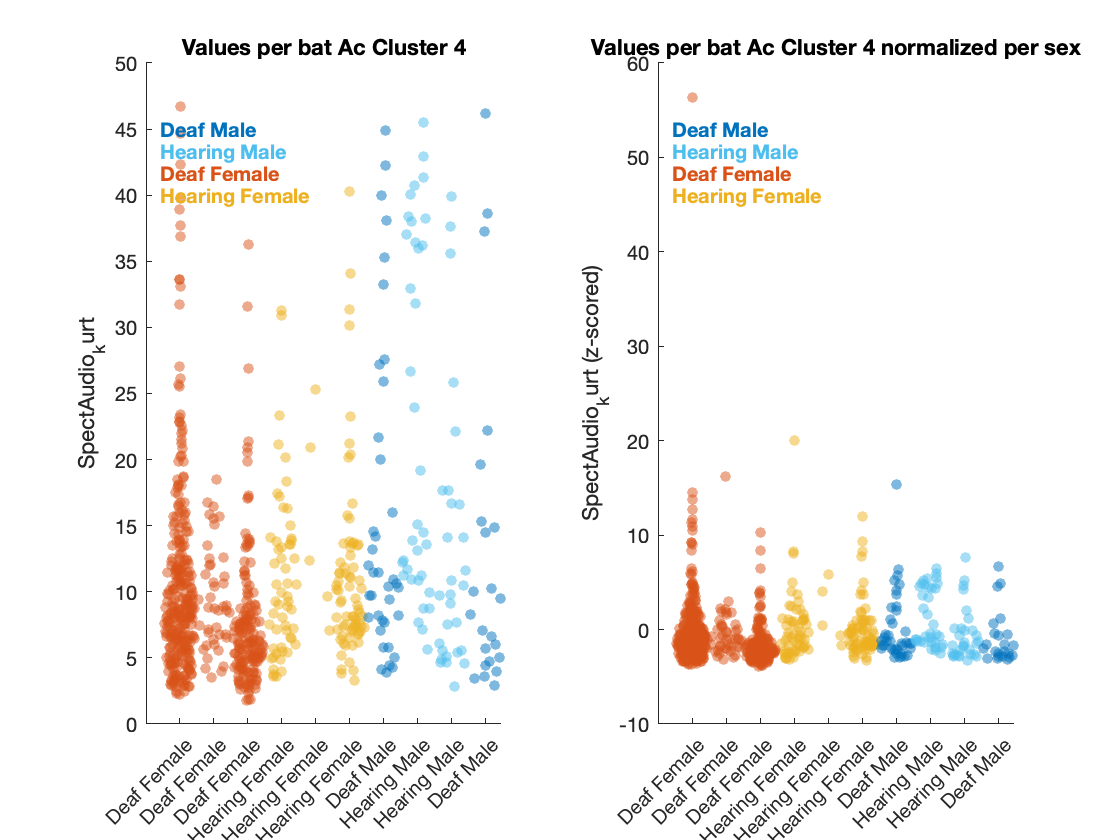

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     4     3371.5    3387.7    -1681.7                                 
    lme      6     3367.4    3391.7    -1677.7    8.0982    2          0.017438


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lme2     5     3373.5    3393.8    -1681.7                                 
    lme      6     3367.4    3391.7    -1677.7    8.0937    1          0.004442


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             427
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3367.4    3391.7    -1677.7          3355.4  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF     pValue        Lower      Upper  
    {'(Intercept)' }         25.172     3.2071     7.8486    423    3.4829e-14     18.868     31.475
    {'Sex_F'       }        -7.4359     4.7715    -1.5584    423       0.11989    -16.815      1.943
    {'HorD_D'      }        -13.494     4.4837    -3.0095    423      0.002773    -22.307    -4.6807
    {'Sex_F:HorD_D'}         23.062     6.5224     3.5359    423 

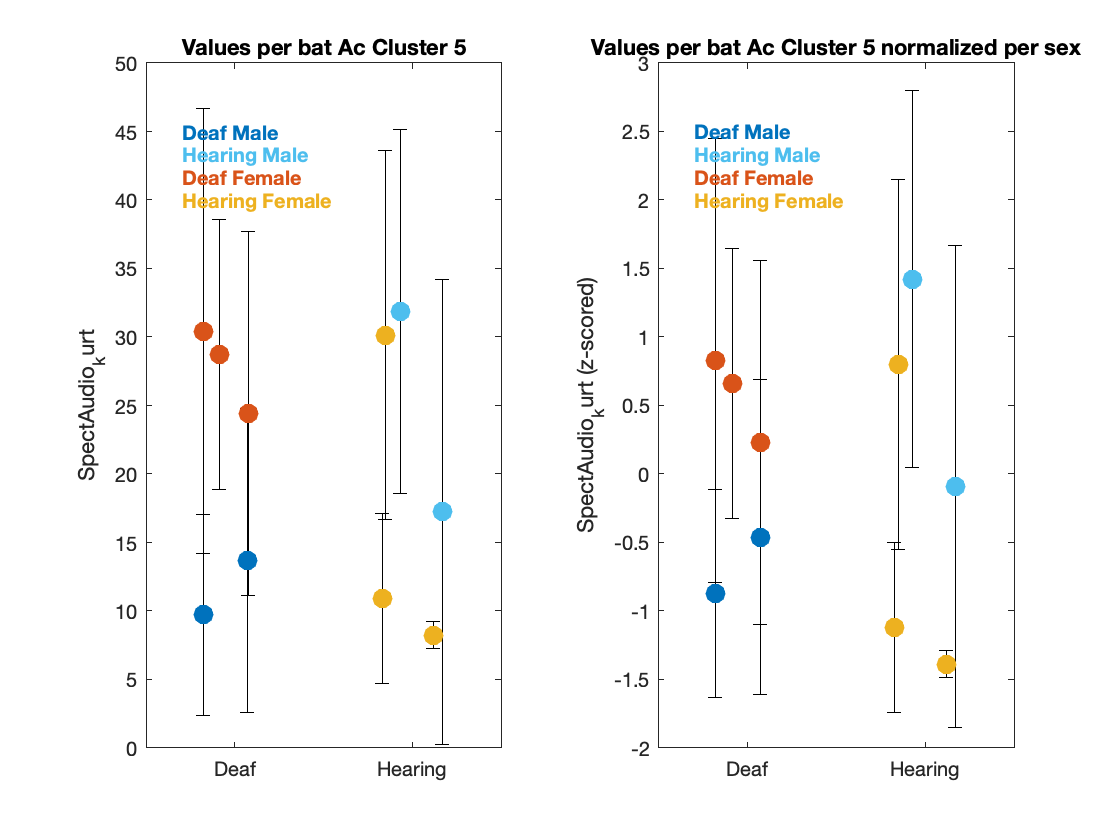

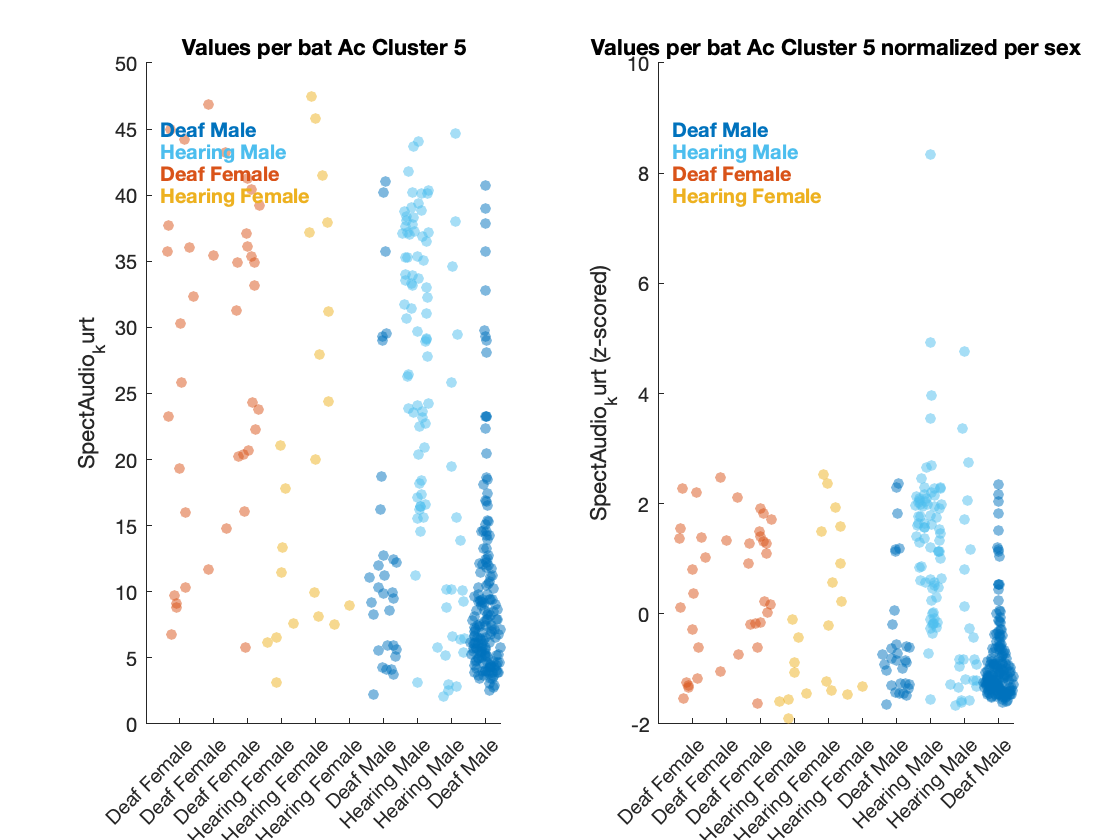

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectAudio_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     4     2793.7    2809.1    -1392.8                                
    lme      6     2793.8    2816.9    -1390.9    3.9141    2          0.14127


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


UCat = unique(AcousticClusters);
% List of variables that were significant at the previous stage analysis
SigAcVars = logical((Pvalue_matrixFDR(:,1)<0.05) + ((Pvalue_matrixFDR(:,2)<0.05) + (Pvalue_matrixFDR(:,3)<0.05)));
AcVars = Tbl.Properties.VariableNames(6:end);
AcVars = AcVars(SigAcVars);

% All P-value of the tests are saved here for FDR correction in the end
Pvalue_matrix_Post_hoc = nan(length(AcVars),2,length(UCat));


for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    for vv=1:length(AcVars)
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1, '*********************     LMEs on %s   ********************\n', AcVars{vv})
        AcVar = Tbl.(sprintf('%s',AcVars{vv}));
        if contains(AcVars{vv}, 'Mic')
            Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)));
            Tbl_local = table(BatID(Ind), CallType(Ind), Sex(Ind),AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        else
            Ind = AcousticClusters==UCat(cc);
            Tbl_local = table(BatID(Ind), CallType(Ind), Sex(Ind),AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        end
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});

        % Full Model
        lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + (1|BatID)');
        % Reduced model without deafening fixed effect
        lmeR = fitlme(Tbl_local, 'AcVar ~ Sex + (1|BatID)');
        TestLME_HD=compare(lmeR, lme)

        Pvalue_matrix_Post_hoc(vv,1,cc) = TestLME_HD.pValue(2);
        if TestLME_HD.pValue(2)<0.05
            lme2 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD + (1|BatID)');
            TestLME_Int_HorD_Sex=compare(lme2, lme)
            Pvalue_matrix_Post_hoc(vv,2,cc) = TestLME_Int_HorD_Sex.pValue(2);
            lme

            % Nice plot 1
            AcVar_mean_pBat = nan(size(BatName));
            AcVar_se_pBat = nan(size(BatName));
            Col_local = nan(length(BatName),3);
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic') || contains(AcVars{vv}, 'Audio')
                    Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
                AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan');%/sum(~isnan(AcVar(Ind)))^0.5
                Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
            end

            AcVar_Male_meanstd(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
            AcVar_Male_meanstd(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
            AcVar_Female_meanstd(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
            AcVar_Female_meanstd(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
            AcVar_meanstd_pBat_sexnorm = nan(length(AcVar_mean_pBat),2);
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic') || contains(AcVars{vv}, 'Audio')
                    Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                if contains(BatSexDeaf{bb}, 'Male')
                    AcVar_meanstd_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Male_meanstd(1))./AcVar_Male_meanstd(2), 'omitnan');
                    AcVar_meanstd_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Male_meanstd(1))./AcVar_Male_meanstd(2), 'omitnan'); %/sum(~isnan(AcVar(Ind)))^0.5
                elseif contains(BatSexDeaf{bb}, 'Female')
                    AcVar_meanstd_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Female_meanstd(1))./AcVar_Female_meanstd(2), 'omitnan');
                    AcVar_meanstd_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Female_meanstd(1))./AcVar_Female_meanstd(2), 'omitnan'); %/sum(~isnan(AcVar(Ind)))^0.5
                end
            end
            figure()
            tiledlayout(1,2)
            nexttile
            XHorD = ones(size(BatSexDeaf)) + (rand(size(BatSexDeaf))-0.5).*0.75;
            XHorD(contains(BatSexDeaf, 'Hearing')) = XHorD(contains(BatSexDeaf, 'Hearing'))+2;

            errorbar(XHorD,AcVar_mean_pBat, AcVar_se_pBat, AcVar_se_pBat, 'k.')
            hold on
            scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled')
            ylabel(sprintf('%s', AcVars{vv}))
            XLim = [0 4];
            set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'})
            hold off
            title(sprintf('Values per bat Ac Cluster %d', UCat(cc)))

            nexttile
            errorbar(XHorD,AcVar_meanstd_pBat_sexnorm(:,1), AcVar_meanstd_pBat_sexnorm(:,2), AcVar_meanstd_pBat_sexnorm(:,2), 'k.')
            hold on
            scatter(XHorD,AcVar_meanstd_pBat_sexnorm(:,1),100, Col_local, 'filled')
            ylabel(sprintf('%s (z-scored)', AcVars{vv}))
            XLim = [0 4];
            set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
            hold off
            title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))


            % Nice plot 2
            figure()
            tiledlayout(1,2)
            nexttile
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic') || contains(AcVars{vv}, 'Audio')
                    Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                hold on
                swarmchart(bb*ones(sum(Ind),1),AcVar(Ind),30,Col_local(bb,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
            end
            hold on
%             errorbar(XHorD,AcVar_mean_pBat, AcVar_std_pBat, AcVar_std_pBat, 'dk','MarkerSize',14,'MarkerFaceColor',Col_local)
            ylabel(sprintf('%s', AcVars{vv}))
%             XLim = [0 4];
%             set(gca, 'XLim', XLim);
            YLim = [0 50];
            set(gca, 'YLim', YLim);
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca, 'XTick', 1:length(BatSexDeaf),'XTickLabel', BatSexDeaf)
            hold off
            title(sprintf('Values per bat Ac Cluster %d', UCat(cc)))

            nexttile
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic') || contains(AcVars{vv}, 'Audio')
                    Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                if contains(BatSexDeaf{bb}, 'Male')
                    DataY=(AcVar(Ind) - AcVar_Male_meanstd(1))./AcVar_Male_meanstd(2);
                elseif contains(BatSexDeaf{bb}, 'Female')
                    DataY = (AcVar(Ind) - AcVar_Female_meanstd(1))./AcVar_Female_meanstd(2);
                end
                hold on
                swarmchart(bb*ones(sum(Ind),1),DataY,30,Col_local(bb,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
            end

%             errorbar(XHorD,AcVar_meanstd_pBat_sexnorm(:,1), AcVar_meanstd_pBat_sexnorm(:,2), AcVar_meanstd_pBat_sexnorm(:,2), 'dk','MarkerSize',14,'MarkerFaceColor',Col_local)
            ylabel(sprintf('%s (z-scored)', AcVars{vv}))
%             XLim = [0 4];
%             set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca, 'XTick', 1:length(BatSexDeaf),'XTickLabel', BatSexDeaf)
            hold off
            title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))

        end
    end
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
end

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
Pvalue_vector = cell(1,length(UCat));
for cc=1:length(UCat)
    Pvalue_vector{cc} = [Pvalue_matrix_Post_hoc(:,1,cc)' Pvalue_matrix_Post_hoc(:,2,cc)'];
end
Pvalue_vector = [Pvalue_vector{:}];
NonNaNInd = ~isnan(Pvalue_vector);
[~,Ord]=sort(Pvalue_vector(NonNaNInd));
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);

Pvalue_matrix_Post_hocFDR = nan(size(Pvalue_matrix_Post_hoc));
NVars = size(Pvalue_matrix_Post_hoc,1);
for cc=1:length(UCat)
    Pvalue_matrix_Post_hocFDR(:,:,cc) = [Pvalue_vectorFDR(((cc-1)*2*NVars) + (1:NVars))' Pvalue_vectorFDR(((cc-1)*2*NVars) + ((NVars+1):2*NVars))'];
end

figure()
tiledlayout(3,2)
for cc=1:length(UCat)
    nexttile
    Im = imagesc(Pvalue_matrix_Post_hocFDR(:,:,cc));
    colorbar()
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
    set(gca, 'XTick', 1:2,'XTickLabel', {'Deafening' 'Interaction'})
    ylabel('Acoustic features')
    xlabel('Fixed Effects')
    title(sprintf('LME pValues Acoustic Cluster %d (FDR corrected)',cc))
end

**Plot examples of extreme points in the distribution**

Call spectrum from hearing male with high spectral kurtosis vs deaf male with low spectral kurtosis

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    
    Col_local = nan(length(BatName),3);
    figure()
    for bb=1:length(BatName)
        if contains(BatSexDeaf{bb}, 'Deaf Male')
            Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))) .* (cellfun(@length, Spect_psdf)~=1) .* (SpectAudio_Kurt<5));
        elseif contains(BatSexDeaf{bb}, 'Hearing Male')
            Ind = logical(MicAudioGood.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))) .* (cellfun(@length, Spect_psdf)~=1) .* (SpectAudio_Kurt<45).* (SpectAudio_Kurt>30));
        else
            continue
        end
        AcVar_mean = mean(cell2mat(Spect_psd_audio(Ind)'),2, 'omitnan');
        AcVar_std = std(cell2mat(Spect_psd_audio(Ind)'),[],2, 'omitnan');%./sum(Ind)^0.5;
        Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
        hold on
%         plot(Spect_psdf{find(Ind,1)},AcVar_mean_pBat(bb,:),'-', 'Color', [Col_local(bb,:) 0.7], 'LineWidth',2)
        shadedErrorBar(Spect_psdf{find(Ind,1)},AcVar_mean, [AcVar_mean'-AcVar_std'; AcVar_mean'-AcVar_std'], {'-', 'Color', Col_local(bb,:), 'LineWidth',2},1)
    end
    hold off
    set(gca,'XLim', [2000 60000])
%     set(gca, 'XScale','log')
    xlabel('Frequency (Hz)')
    ylabel('Normalized Power')
    title('Bat individual spectrum corrected by auditory loss function')
end

**Plot 10 example spectrograms for acoustic category 5**

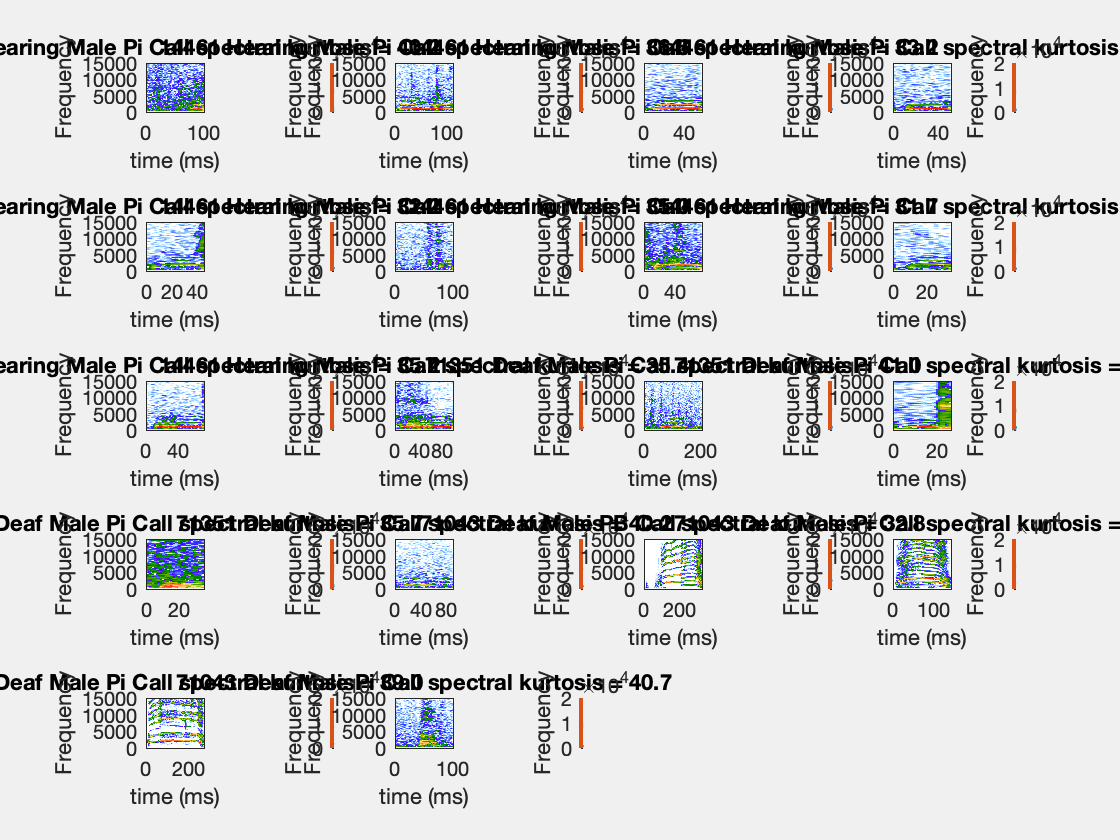

File 1/237
File 2/237
File 3/237
File 4/237
File 5/237
File 6/237
File 7/237
File 8/237


No Data for this file 200123_0958_VocExtractData8_200.mat


File 9/237
File 10/237
File 11/237
File 12/237
File 13/237
File 14/237
File 15/237
File 16/237
File 17/237
File 18/237
File 19/237
File 20/237
File 21/237
File 22/237
File 23/237
File 24/237
File 25/237
File 26/237
File 27/237
File 28/237
File 29/237
File 30/237
File 31/237
File 32/237
File 33/237
File 34/237
File 35/237
File 36/237
File 37/237
File 38/237
File 39/237
File 40/237
File 41/237
File 42/237
File 43/237
File 44/237


No Data for this file 200124_1013_VocExtractData21_200.mat


File 45/237
File 46/237
File 47/237
File 48/237
File 49/237
File 50/237
File 51/237
File 52/237
File 53/237
File 54/237
File 55/237
File 56/237
File 57/237
File 58/237
File 59/237
File 60/237
File 61/237
File 62/237
File 63/237
File 64/237
File 65/237
File 66/237
File 67/237
File 68/237
File 69/237
File 70/237
File 71/237
File 72/237
File 73/237
File 74/237
File 75/237
File 76/237
File 77/237
File 78/237
File 79/237
File 80/237
File 81/237
File 82/237
File 83/237
File 84/237
File 85/237
File 86/237
File 87/237
File 88/237
File 89/237
File 90/237
File 91/237
File 92/237
File 93/237
File 94/237
File 95/237
File 96/237
File 97/237
File 98/237
File 99/237
File 100/237
File 101/237
File 102/237
File 103/237
File 104/237
File 105/237
File 106/237
File 107/237
File 108/237


No Data for this file 200127_0959_VocExtractData27_200.mat


File 109/237
File 110/237
File 111/237
File 112/237
File 113/237
File 114/237
File 115/237
File 116/237
File 117/237
File 118/237
File 119/237
File 120/237
File 121/237
File 122/237
File 123/237
File 124/237
File 125/237
File 126/237


No Data for this file 200127_0959_VocExtractData43_200.mat


File 127/237
File 128/237
File 129/237
File 130/237
File 131/237
File 132/237
File 133/237
File 134/237
File 135/237
File 136/237
File 137/237
File 138/237
File 139/237
File 140/237
File 141/237
File 142/237
File 143/237
File 144/237
File 145/237
File 146/237
File 147/237
File 148/237
File 149/237
File 150/237
File 151/237
File 152/237
File 153/237
File 154/237
File 155/237
File 156/237
File 157/237
File 158/237
File 159/237
File 160/237
File 161/237
File 162/237
File 163/237
File 164/237
File 165/237
File 166/237
File 167/237
File 168/237
File 169/237
File 170/237
File 171/237
File 172/237
File 173/237
File 174/237
File 175/237
File 176/237
File 177/237
File 178/237
File 179/237
File 180/237
File 181/237
File 182/237
File 183/237
File 184/237
File 185/237
File 186/237
File 187/237
File 188/237
File 189/237
File 190/237
File 191/237
File 192/237
File 193/237
File 194/237
File 195/237
File 196/237
File 197/237
File 198/237
File 199/237
File 200/237
File 201/237
File 202/237
File 203/237

File 226/237
File 227/237
File 228/237
File 229/237
File 230/237
File 231/237
File 232/237
File 233/237
File 234/237
File 235/237
File 236/237
File 237/237


cc=5;
NumEx = 20;
% IndDMLowK = find(MicAudioGood.*(AcousticClusters==UCat(cc)) .* (cellfun(@length, Spect_psdf)~=1) .* (SpectAudio_Kurt<5) .* (strcmp(SexDeaf, 'DM')),NumEx/2);
IndDMLowK = find(MicAudioGood.*(AcousticClusters==UCat(cc)) .* (cellfun(@length, Spect_psdf)~=1) .* (SpectAudio_Kurt<45).* (SpectAudio_Kurt>30) .* (strcmp(SexDeaf, 'DM')),NumEx/2);
% IndHMHighK = find(MicAudioGood.*(AcousticClusters==UCat(cc)) .* (cellfun(@length, Spect_psdf)~=1) .* (SpectAudio_Kurt<5).*  (strcmp(SexDeaf, 'HM')),NumEx/2);
IndHMHighK = find(MicAudioGood.*(AcousticClusters==UCat(cc)) .* (cellfun(@length, Spect_psdf)~=1) .* (SpectAudio_Kurt<45).* (SpectAudio_Kurt>30) .* (strcmp(SexDeaf, 'HM')),NumEx/2);
figure()
set(gcf,'Visible','on')
tiledlayout(NumEx/4,16)
VocCount = nan(NF,1);
Ex_count = 0;
warning('off', 'MATLAB:Python:UnsupportedLoad')
for nf = 1:NF
    fprintf(1,'File %d/%d\n', nf, NF);
    DataFile = load(fullfile(DataFiles(nf).folder, DataFiles(nf).name));
    if isempty(DataFile.BioSoundCalls)
        fprintf(1,'No Data for this file %s\n', DataFiles(nf).name)
        continue
    end
    VVCount = 0;
    for vv=1:size(DataFile.BioSoundFilenames,1)
        if isempty(DataFile.BioSoundFilenames{vv,2}) % That was probably an noise that have not been kept
            continue
        end
        [~,Name,~] = fileparts(DataFile.BioSoundFilenames{vv,2});
        NC_local = sum(DataFile.ManualAnnotationOK{vv}==1);
        IndCall = find(DataFile.ManualAnnotationOK{vv}==1);
        if iscell(DataFile.ManualCallType{vv}) && sum(~cellfun('isempty',DataFile.ManualCallType{vv}))~= NC_local
            error('There is an issue with the identification of syllables')
        elseif ~iscell(DataFile.ManualCallType{vv}) && ~isempty(DataFile.ManualCallType{vv})~= NC_local
            error('There is an issue with the identification of syllables')
        end
        BatInd = strfind(Name,'Bat');
        for ee=1:NC_local
            cc = IndCall(ee);
            VVCount = VVCount +1;
            if any(IndDMLowK==VVCount+sum(VocCount, 'omitnan')) || any(IndHMHighK==VVCount+sum(VocCount, 'omitnan'))
                Ex_count = Ex_count+1;
                BatID_local = Name(BatInd+(3:7));
                CallType = DataFile.ManualCallType{vv}{cc};
                if isfield(DataFile.BioSoundCalls{vv,1}, 'spectro_elmts')
                    Spectro = DataFile.BioSoundCalls{vv,1}.spectro_elmts{cc};
                    Fo = DataFile.BioSoundCalls{vv,1}.fo_elmts{cc};
                    To = DataFile.BioSoundCalls{vv,1}.to_elmts{cc};
                else
                    Spectro = DataFile.BioSoundCalls{vv,1}.spectro;
                    Fo = DataFile.BioSoundCalls{vv,1}.fo;
                    To = DataFile.BioSoundCalls{vv,1}.to;
                end
                nexttile([1 3])
                DBNOISE =50;
                f_low = 0;
                F_high = 15000;
                logB = Spectro;
                maxB = max(max(logB));
                minB = maxB-DBNOISE;
                imagesc(To*1000,Fo,logB);          % to is in seconds
                axis xy;
                caxis('manual');
                caxis([minB maxB]);
                cmap = spec_cmap();
                colormap(cmap);
        %         colorbar()
        
                v_axis = axis;
                v_axis(3)=f_low;
                v_axis(4)=F_high;
                axis(v_axis);
                xlabel('time (ms)'), ylabel('Frequency');
                if any(IndDMLowK==VVCount+sum(VocCount, 'omitnan'))
                    title(sprintf('%s Deaf Male %s Call spectral kurtosis = %.1f', BatID_local, CallType,SpectAudio_Kurt(VVCount+sum(VocCount, 'omitnan'))))
                elseif any(IndHMHighK==VVCount+sum(VocCount, 'omitnan'))
                    title(sprintf('%s Hearing Male %s Call spectral kurtosis = %.1f', BatID_local,CallType, SpectAudio_Kurt(VVCount+sum(VocCount, 'omitnan'))))
                end
                nexttile([1 1])
                plot(Spect_psd{VVCount+sum(VocCount, 'omitnan')}, Spect_psdf{VVCount+sum(VocCount, 'omitnan')},'LineWidth',2)
                hold on
                plot(Spect_psd_audio{VVCount+sum(VocCount, 'omitnan')}, Spect_psdf{VVCount+sum(VocCount, 'omitnan')},'LineWidth',2)
                ylim([0 20000])
                xlabel('Power')
                ylabel('Frequency')
                hold off
            end
            if Ex_count == NumEx
                break
            end
        end
        if Ex_count == NumEx
            break
        end

    end
    VocCount(nf) = VVCount;
    if Ex_count == NumEx
        break
    end
end

warning('on', 'MATLAB:Python:UnsupportedLoad')

function [Quartile_freq, MeanSpect, StdSpect, KurtosisSpect, SkewSpect, EntropySpect] = spec_env_paramEstimate(Psd,Freqs, F_high)

% Find quartile power
    Cum_power = cumsum(Psd);
    Tot_power = sum(Psd);
    Quartile_freq = nan(1,3);
    Quartile_values = [0.25, 0.5, 0.75];
    Nfreqs = length(Cum_power);
    iq = 1;
    for ifreq=1:Nfreqs
        if (Cum_power(ifreq) > Quartile_values(iq)*Tot_power)
            Quartile_freq(iq) = Freqs(ifreq);
            iq = iq+1;
            if (iq > 3)
                break;
            end
        end
    end
    
    % Calculate the momentum of the spectral envelope
% Find skewness, kurtosis and entropy for power spectrum below
    % f_high
    Ind_fmax = Nfreqs;
    for ifreq=1:Nfreqs
        if (Freqs(ifreq) > F_high )
            Ind_fmax = ifreq;
            break;
        end
    end
    
    % Description of spectral enveloppe
    Spectdata = Psd(1:Ind_fmax);
    Freqdata = Freqs(1:Ind_fmax);
    Spectdata = Spectdata./sum(Spectdata);
    MeanSpect = sum(Freqdata.*Spectdata);
    StdSpect = sqrt(sum(Spectdata.*((Freqdata-MeanSpect).^2)));
    SkewSpect = sum(Spectdata.*(Freqdata-MeanSpect).^3);
    SkewSpect = SkewSpect./(StdSpect.^3);
    KurtosisSpect = sum(Spectdata.*(Freqdata-MeanSpect).^4);
    KurtosisSpect = KurtosisSpect./(StdSpect.^4);
    EntropySpect = -sum(Spectdata.*log2(Spectdata))/log2(Ind_fmax);
end
    